# Spike Count Analysis - Entropy & Fano Factor

## Create a folder for the processed data that will be compile and analyzed

targetdir = "C:\Users\LPASCU2\OneDrive - Emory University\MATLAB_CODE\ephys-songbird\data\processed\compiled_cases";
figct = 0;

## Compile data that will be analyzed.

### Cases subset: JUVENILE

juv_early = struct();
getTrials = {};
juv_params = {};

#### CHOOSE CASES FOR ANALYSIS 

% Extract spikes starting from t-premotor_win (sec prior to syllable onset)
premotor_win = 0.2; % parameter for making new case file or finding an existing case file 

cd 'J:\MINI DATASET'

%%% Query for BIRD 1 %%%
birdname1 = 'br177yw112';
days1 = [62 661 662 73 86 88];%[62 661 662 68 73 86 88];
syls1 = 'bcdghjkrm';
file_exist = '2024_02_20'; % date file was generated,'YYYY-MM-DD', if making new files

% Extract Data from given bird, neuron/days, syls into a Data Structure
getTrials = get_spikes_acs_data(birdname1,days1,syls1,premotor_win,file_exist);

day = 62

Done. There are 151 clean trials and 0 trials with artifact.
Elapsed time is 0.738503 seconds.
Done. There are 145 clean trials and 0 trials with artifact.
Elapsed time is 0.708881 seconds.
Done. There are 177 clean trials and 0 trials with artifact.
Elapsed time is 0.714931 seconds.
Done. There are 6 clean trials and 0 trials with artifact.
Elapsed time is 0.597594 seconds.
Done. There are 4 clean trials and 0 trials with artifact.
Elapsed time is 0.621692 seconds.


day = 661

Done. There are 75 clean trials and 0 trials with artifact.
Elapsed time is 1.323000 seconds.
Done. There are 71 clean trials and 0 trials with artifact.
Elapsed time is 0.675075 seconds.
Done. There are 79 clean trials and 0 trials with artifact.
Elapsed time is 0.659654 seconds.
Done. There are 2 clean trials and 0 trials with artifact.
Elapsed time is 0.608384 seconds.
Done. There are 21 clean trials and 0 trials with artifact.
Elapsed time is 0.619958 seconds.
Done. There are 18 clean trials and 0 trials with artifact.
Elapsed time is 0.612152 seconds.
Done. There are 12 clean trials and 0 trials with artifact.
Elapsed time is 0.619978 seconds.


day = 662

Done. There are 112 clean trials and 0 trials with artifact.
Elapsed time is 2.585913 seconds.
Done. There are 104 clean trials and 0 trials with artifact.
Elapsed time is 1.156178 seconds.
Done. There are 155 clean trials and 0 trials with artifact.
Elapsed time is 1.195155 seconds.
Done. There are 2 clean trials and 0 trials with artifact.
Elapsed time is 1.098996 seconds.
Done. There are 1 clean trials and 0 trials with artifact.
Elapsed time is 1.026459 seconds.
Done. There are 70 clean trials and 0 trials with artifact.
Elapsed time is 1.146729 seconds.
Done. There are 58 clean trials and 0 trials with artifact.
Elapsed time is 1.125513 seconds.
Done. There are 23 clean trials and 0 trials with artifact.
Elapsed time is 1.124597 seconds.


day = 73

Done. There are 347 clean trials and 0 trials with artifact.
Elapsed time is 16.745781 seconds.
Done. There are 553 clean trials and 0 trials with artifact.
Elapsed time is 7.652652 seconds.
Done. There are 532 clean trials and 0 trials with artifact.
Elapsed time is 4.475873 seconds.
Done. There are 329 clean trials and 0 trials with artifact.
Elapsed time is 4.366607 seconds.
Done. There are 247 clean trials and 0 trials with artifact.
Elapsed time is 4.307390 seconds.
Done. There are 252 clean trials and 0 trials with artifact.
Elapsed time is 4.134879 seconds.
Done. There are 208 clean trials and 0 trials with artifact.
Elapsed time is 4.236243 seconds.
Done. There are 195 clean trials and 0 trials with artifact.
Elapsed time is 4.241559 seconds.
Done. There are 352 clean trials and 0 trials with artifact.
Elapsed time is 4.363971 seconds.


day = 86

Done. There are 497 clean trials and 0 trials with artifact.
Elapsed time is 12.165349 seconds.
Done. There are 689 clean trials and 0 trials with artifact.
Elapsed time is 6.584801 seconds.
Done. There are 729 clean trials and 0 trials with artifact.
Elapsed time is 5.883942 seconds.
Done. There are 605 clean trials and 0 trials with artifact.
Elapsed time is 5.725072 seconds.
Done. There are 262 clean trials and 0 trials with artifact.
Elapsed time is 5.375219 seconds.
Done. There are 262 clean trials and 0 trials with artifact.
Elapsed time is 5.326875 seconds.
Done. There are 292 clean trials and 0 trials with artifact.
Elapsed time is 5.382955 seconds.
Done. There are 259 clean trials and 0 trials with artifact.
Elapsed time is 5.292442 seconds.
Done. There are 301 clean trials and 0 trials with artifact.
Elapsed time is 5.317386 seconds.


day = 88

Done. There are 488 clean trials and 0 trials with artifact.
Elapsed time is 22.894669 seconds.
Done. There are 727 clean trials and 0 trials with artifact.
Elapsed time is 19.730474 seconds.
Done. There are 728 clean trials and 0 trials with artifact.
Elapsed time is 14.890560 seconds.
Done. There are 636 clean trials and 0 trials with artifact.
Elapsed time is 7.370962 seconds.
Done. There are 307 clean trials and 0 trials with artifact.
Elapsed time is 5.269109 seconds.
Done. There are 314 clean trials and 0 trials with artifact.
Elapsed time is 5.174255 seconds.
Done. There are 348 clean trials and 0 trials with artifact.
Elapsed time is 5.181676 seconds.
Done. There are 320 clean trials and 0 trials with artifact.
Elapsed time is 5.153773 seconds.
Done. There are 501 clean trials and 0 trials with artifact.
Elapsed time is 5.258830 seconds.



%%% Query for BIRD 2 %%%
birdname2 = 'br173gr56';
days2 = [78 801 802 803 811 812 153]; %[78 801 802 803 811 812];
syls2 = 'bcfghjkpqrs'; %'bcfghjkpqrs'
file_exist = '2024_02_20';

getTrials2 = get_spikes_acs_data(birdname2,days2,syls2,premotor_win,file_exist);

day = 78

Done. There are 151 clean trials and 0 trials with artifact.
Elapsed time is 10.693050 seconds.
Done. There are 444 clean trials and 0 trials with artifact.
Elapsed time is 2.559221 seconds.
Done. There are 134 clean trials and 0 trials with artifact.
Elapsed time is 2.357102 seconds.
Done. There are 160 clean trials and 0 trials with artifact.
Elapsed time is 2.285697 seconds.
Done. There are 91 clean trials and 0 trials with artifact.
Elapsed time is 2.228655 seconds.
Done. There are 255 clean trials and 0 trials with artifact.
Elapsed time is 2.358360 seconds.
Done. There are 259 clean trials and 0 trials with artifact.
Elapsed time is 2.371836 seconds.
Done. There are 132 clean trials and 0 trials with artifact.
Elapsed time is 2.286461 seconds.
Done. There are 111 clean trials and 0 trials with artifact.
Elapsed time is 2.310487 seconds.
Done. There are 112 clean trials and 0 trials with artifact.
Elapsed time is 2.262015 seconds.
Done. There are 112 clean trials and 0 trials with

day = 801

Done. There are 41 clean trials and 0 trials with artifact.
Elapsed time is 2.817827 seconds.
Done. There are 125 clean trials and 0 trials with artifact.
Elapsed time is 0.745918 seconds.
Done. There are 40 clean trials and 0 trials with artifact.
Elapsed time is 0.669162 seconds.
Done. There are 34 clean trials and 0 trials with artifact.
Elapsed time is 0.659594 seconds.
Done. There are 31 clean trials and 0 trials with artifact.
Elapsed time is 0.676894 seconds.
Done. There are 78 clean trials and 0 trials with artifact.
Elapsed time is 0.705206 seconds.
Done. There are 77 clean trials and 0 trials with artifact.
Elapsed time is 0.726599 seconds.
Done. There are 41 clean trials and 0 trials with artifact.
Elapsed time is 0.681589 seconds.
Done. There are 38 clean trials and 0 trials with artifact.
Elapsed time is 0.670832 seconds.
Done. There are 21 clean trials and 0 trials with artifact.
Elapsed time is 0.673751 seconds.
Done. There are 38 clean trials and 0 trials with artifact.

day = 802

Done. There are 17 clean trials and 0 trials with artifact.
Elapsed time is 0.926781 seconds.
Done. There are 55 clean trials and 0 trials with artifact.
Elapsed time is 0.261986 seconds.
Done. There are 17 clean trials and 0 trials with artifact.
Elapsed time is 0.249354 seconds.
Done. There are 15 clean trials and 0 trials with artifact.
Elapsed time is 0.244425 seconds.
Done. There are 14 clean trials and 0 trials with artifact.
Elapsed time is 0.231309 seconds.
Done. There are 33 clean trials and 0 trials with artifact.
Elapsed time is 0.243941 seconds.
Done. There are 31 clean trials and 0 trials with artifact.
Elapsed time is 0.244097 seconds.
Done. There are 22 clean trials and 0 trials with artifact.
Elapsed time is 0.250267 seconds.
Done. There are 16 clean trials and 0 trials with artifact.
Elapsed time is 0.246532 seconds.
Done. There are 13 clean trials and 0 trials with artifact.
Elapsed time is 0.236452 seconds.
Done. There are 16 clean trials and 0 trials with artifact.


day = 803

Done. There are 75 clean trials and 0 trials with artifact.
Elapsed time is 3.675531 seconds.
Done. There are 213 clean trials and 0 trials with artifact.
Elapsed time is 1.043894 seconds.
Done. There are 72 clean trials and 0 trials with artifact.
Elapsed time is 0.953367 seconds.
Done. There are 69 clean trials and 0 trials with artifact.
Elapsed time is 0.906026 seconds.
Done. There are 41 clean trials and 0 trials with artifact.
Elapsed time is 0.896696 seconds.
Done. There are 149 clean trials and 0 trials with artifact.
Elapsed time is 0.998565 seconds.
Done. There are 147 clean trials and 0 trials with artifact.
Elapsed time is 0.971838 seconds.
Done. There are 79 clean trials and 0 trials with artifact.
Elapsed time is 0.933008 seconds.
Done. There are 65 clean trials and 0 trials with artifact.
Elapsed time is 0.905179 seconds.
Done. There are 4 clean trials and 0 trials with artifact.
Elapsed time is 0.872158 seconds.
Done. There are 65 clean trials and 0 trials with artifact

day = 811

Done. There are 240 clean trials and 0 trials with artifact.
Elapsed time is 10.101052 seconds.
Done. There are 607 clean trials and 0 trials with artifact.
Elapsed time is 2.929521 seconds.
Done. There are 235 clean trials and 0 trials with artifact.
Elapsed time is 2.543738 seconds.
Done. There are 225 clean trials and 0 trials with artifact.
Elapsed time is 2.574787 seconds.
Done. There are 225 clean trials and 0 trials with artifact.
Elapsed time is 2.535632 seconds.
Done. There are 481 clean trials and 0 trials with artifact.
Elapsed time is 2.762285 seconds.
Done. There are 476 clean trials and 0 trials with artifact.
Elapsed time is 2.829038 seconds.
Done. There are 222 clean trials and 0 trials with artifact.
Elapsed time is 2.519430 seconds.
Done. There are 186 clean trials and 0 trials with artifact.
Elapsed time is 2.480642 seconds.
Done. There are 183 clean trials and 0 trials with artifact.
Elapsed time is 2.479747 seconds.
Done. There are 179 clean trials and 0 trials wit

day = 812

Done. There are 136 clean trials and 0 trials with artifact.
Elapsed time is 4.332558 seconds.
Done. There are 348 clean trials and 0 trials with artifact.
Elapsed time is 1.850159 seconds.
Done. There are 132 clean trials and 0 trials with artifact.
Elapsed time is 1.611525 seconds.
Done. There are 126 clean trials and 0 trials with artifact.
Elapsed time is 1.647023 seconds.
Done. There are 127 clean trials and 0 trials with artifact.
Elapsed time is 1.638007 seconds.
Done. There are 278 clean trials and 0 trials with artifact.
Elapsed time is 1.758356 seconds.
Done. There are 274 clean trials and 0 trials with artifact.
Elapsed time is 1.745393 seconds.
Done. There are 130 clean trials and 0 trials with artifact.
Elapsed time is 1.632240 seconds.
Done. There are 110 clean trials and 0 trials with artifact.
Elapsed time is 1.567744 seconds.
Done. There are 109 clean trials and 0 trials with artifact.
Elapsed time is 1.567206 seconds.
Done. There are 105 clean trials and 0 trials with

day = 153

Done. There are 135 clean trials and 0 trials with artifact.
Elapsed time is 4.403647 seconds.
Done. There are 250 clean trials and 0 trials with artifact.
Elapsed time is 1.253392 seconds.
Done. There are 134 clean trials and 0 trials with artifact.
Elapsed time is 1.180645 seconds.
Done. There are 134 clean trials and 0 trials with artifact.
Elapsed time is 1.151697 seconds.
Done. There are 134 clean trials and 0 trials with artifact.
Elapsed time is 1.155283 seconds.
Done. There are 259 clean trials and 0 trials with artifact.
Elapsed time is 1.259774 seconds.
Done. There are 257 clean trials and 0 trials with artifact.
Elapsed time is 1.229838 seconds.
Done. There are 127 clean trials and 0 trials with artifact.
Elapsed time is 1.155550 seconds.
Done. There are 127 clean trials and 0 trials with artifact.
Elapsed time is 1.149232 seconds.



% Combine Cases
struct1 = getTrials; struct2 = getTrials2; 
names = [fieldnames(struct1); fieldnames(struct2)];
struct3 = cell2struct([struct2cell(struct1); struct2cell(struct2)], names, 1);
allCases = struct3;

% Save compiled cases
cd(targetdir)
savefn = 'compiled_cases_2024_02_20.mat';
save(savefn,"allCases","birdname1", "days1", "syls1", "birdname2", "days2", "syls2");

samCases = struct with fields:
        mean_fr: [34×1 double]
        entropy: [34×1 double]
        case_sz: [34×1 double]
      casenames: {34×1 cell}
       mean_isi: [34×1 double]
       mean_ifr: [34×1 double]
    fano_factor: [34×1 double]


Split br177yw12 syllable 'd' syllables into two clusters for days 73,86,88.

% Load casefiles
cd(targetdir)
loadfn = 'compiled_cases_2024_02_20.mat';
load(loadfn,"allCases","birdname1", "days1", "syls1", "birdname2", "days2", "syls2");

% Array of days you want to loop through
days = [661 73, 86, 88];

% Loop through each day
for i = 1:length(days)
    clear X f1 durs clusterIndices recname acoustics
    day = days(i);
    
    % Construct the variable name for the current day
    neuralcase_varname = sprintf('allCases.br177yw112_d_day%d', day);
    
    % Dynamically access the variable for the current day
    neuralcase = eval(neuralcase_varname);
    
    % Extract data for the current neuralcase
    f1 = neuralcase.weighted_avg_pitch;
    durs = neuralcase.syl_ons_offs(:,2) - neuralcase.syl_ons_offs(:,1);
    recname = neuralcase.recfilename;
    
    % Plotting
    figure; histogram(f1); title(['br177yw112: Day ', num2str(day), ', syllable d']); xlabel('pitch');
    figure; histogram(durs); title(['br177yw112: Day ', num2str(day), ', syllable d']); xlabel('duration (s)');
    
    figure; scatter(durs, f1);
    xlabel('syllable duration (sec)');
    ylabel('fundamental frequency');

    % create matrix of k-means
    acoustics = table(f1, durs);
    X(:,1) = f1; 
    X(:,2) = durs;
    rng('default')


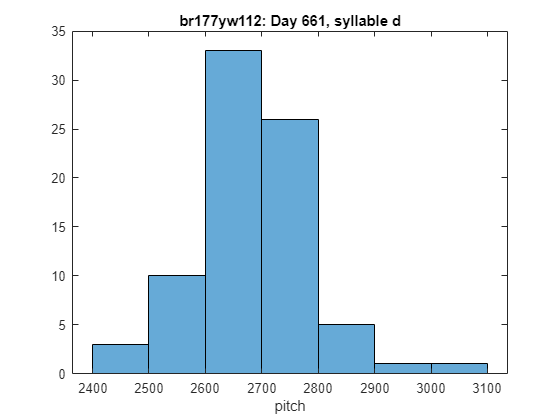

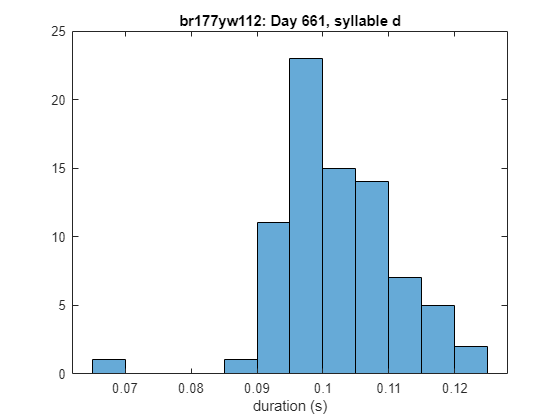

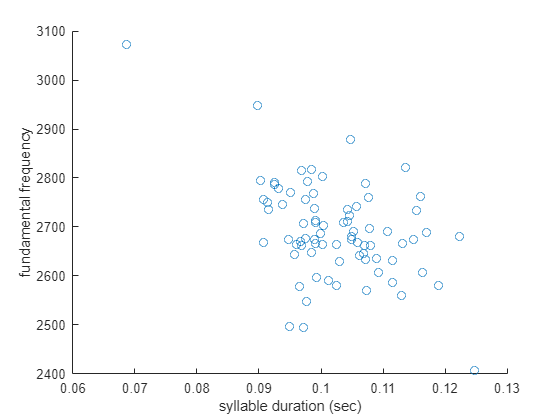

pf =   Histogram with properties:

             Data: [27×1 double]
           Values: [0.2593 0.4815 0.1481 0.0370 0.0370 0 0 0.0370]
          NumBins: 8
         BinEdges: [2700 2750 2800 2850 2900 2950 3000 3050 3100]
         BinWidth: 50
        BinLimits: [2700 3100]
    Normalization: 'probability'
        FaceColor: 'none'
        EdgeColor: 'auto'

  Show all properties


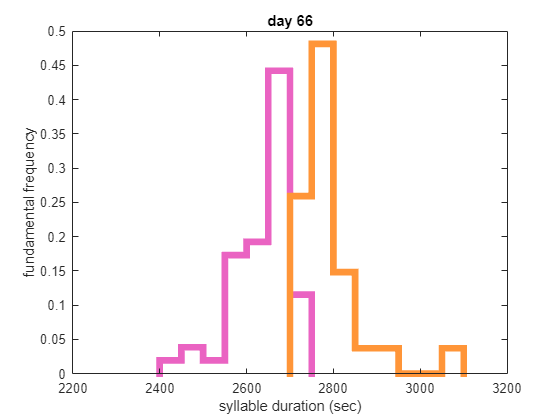

case_ID = 'br177yw112_d1_day661'

case_ID = 'br177yw112_d2_day661'

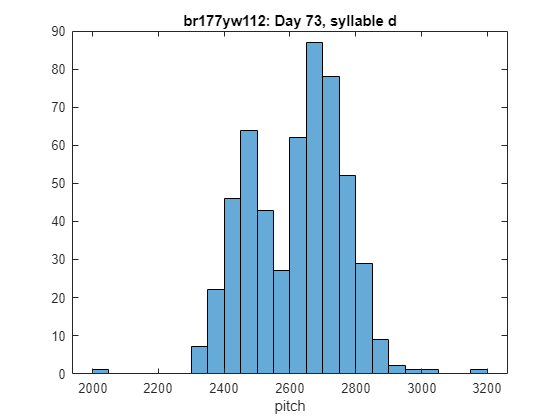

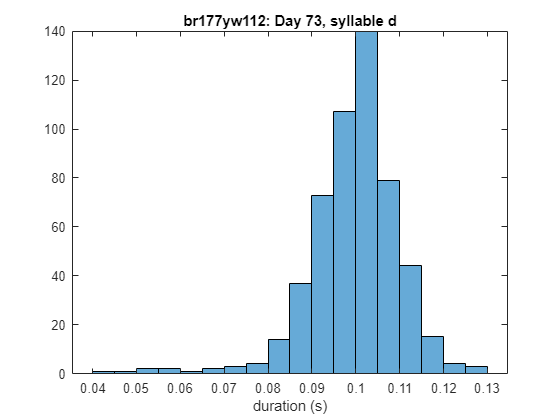

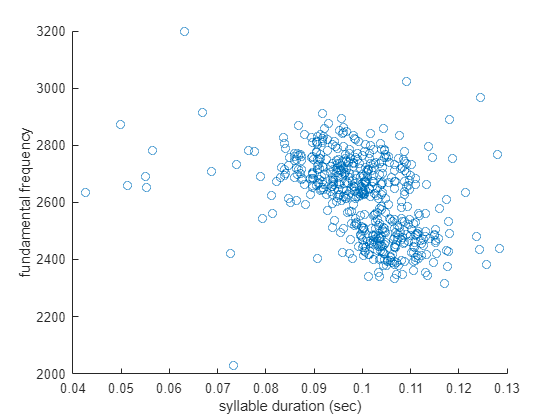

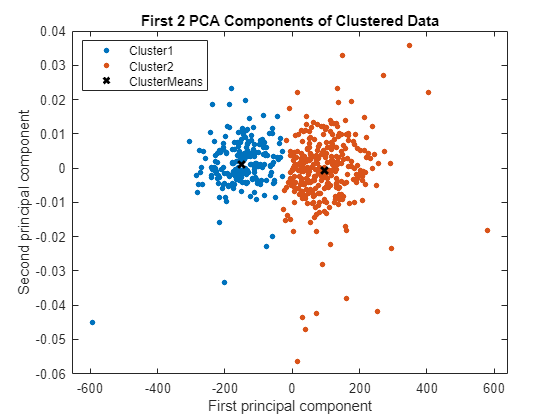

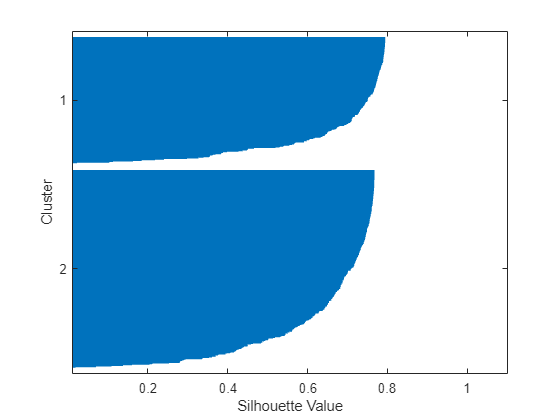

pf =   Histogram with properties:

             Data: [324×1 double]
           Values: [0.0062 0.1914 0.2685 0.2407 0.1605 0.0895 0.0278 0.0062 0.0031 0.0031 0 0 0.0031]
          NumBins: 13
         BinEdges: [2550 2600 2650 2700 2750 2800 2850 2900 2950 3000 3050 3100 3150 3200]
         BinWidth: 50
        BinLimits: [2550 3200]
    Normalization: 'probability'
        FaceColor: 'none'
        EdgeColor: 'auto'

  Show all properties


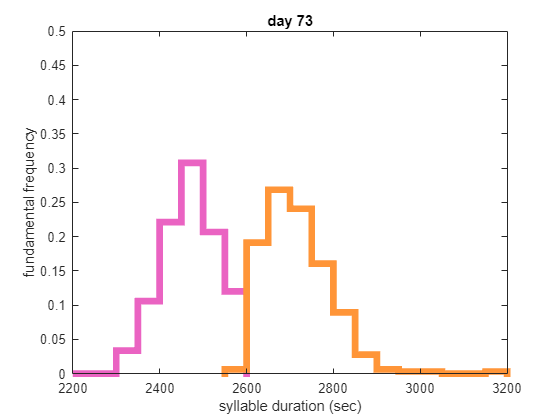

case_ID = 'br177yw112_d1_day73'

case_ID = 'br177yw112_d2_day73'

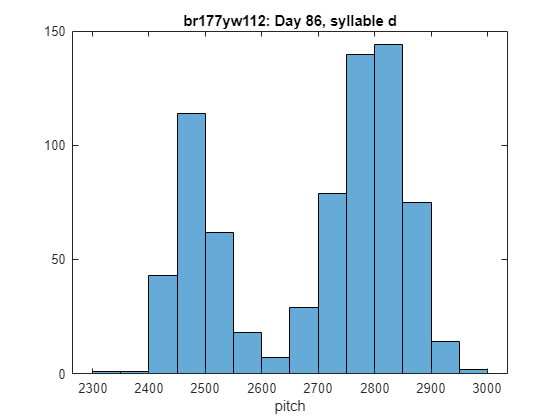

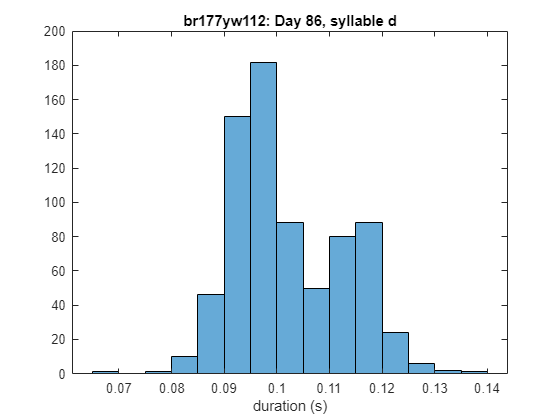

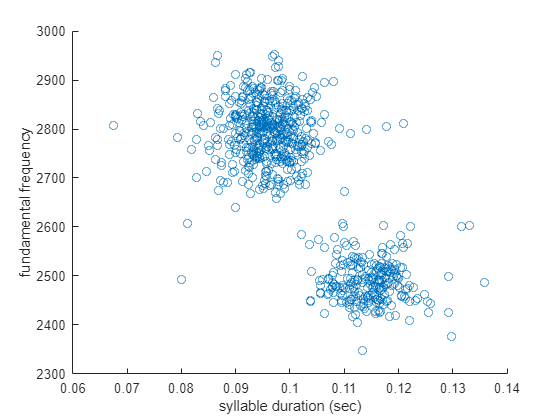

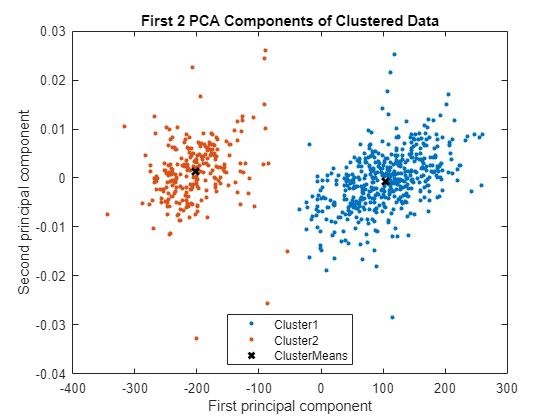

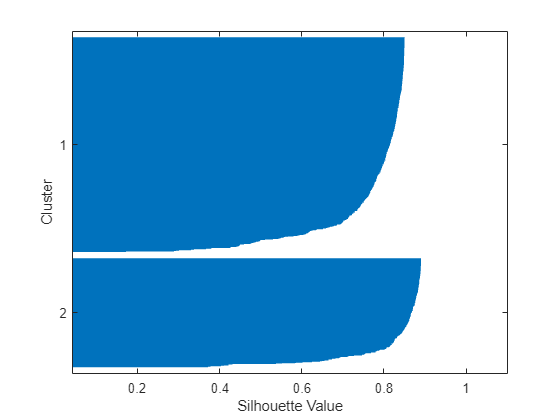

pf =   Histogram with properties:

             Data: [483×1 double]
           Values: [0.0600 0.1636 0.2899 0.2981 0.1553 0.0290 0.0041]
          NumBins: 7
         BinEdges: [2650 2700 2750 2800 2850 2900 2950 3000]
         BinWidth: 50
        BinLimits: [2650 3000]
    Normalization: 'probability'
        FaceColor: 'none'
        EdgeColor: 'auto'

  Show all properties


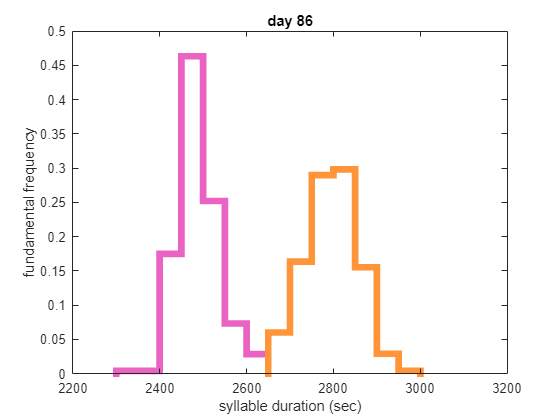

case_ID = 'br177yw112_d1_day86'

case_ID = 'br177yw112_d2_day86'

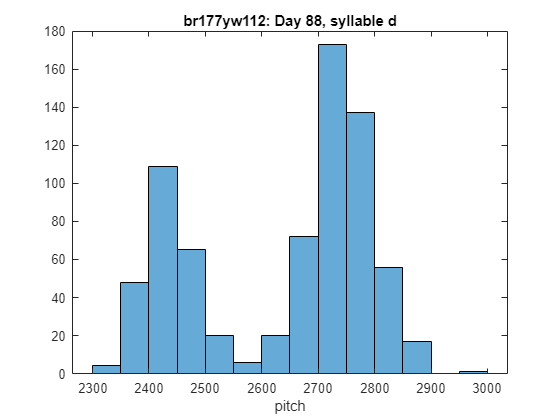

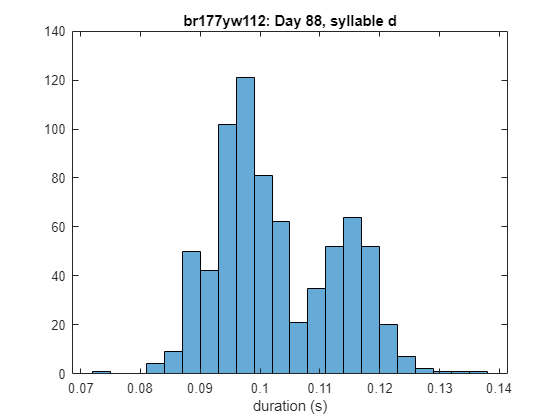

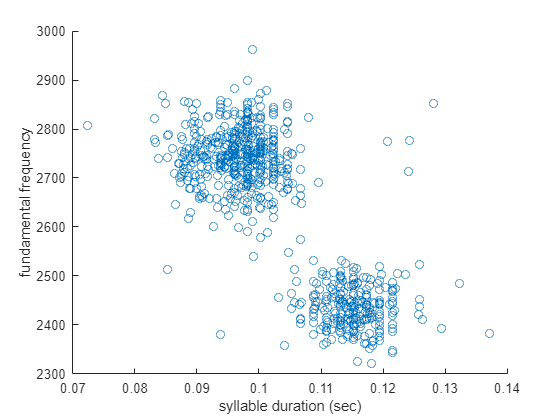

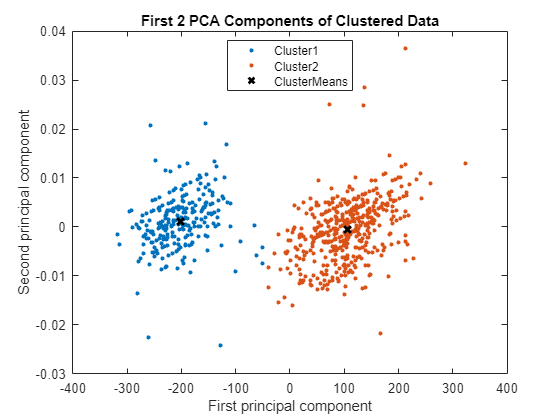

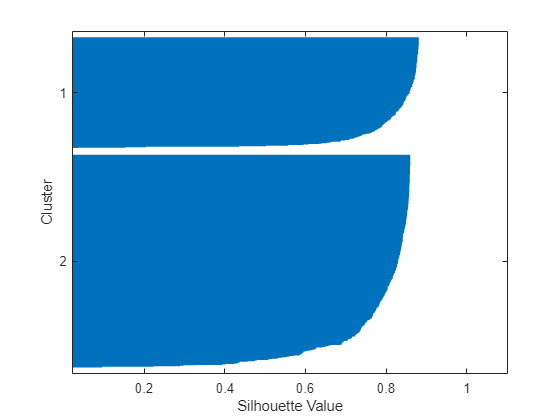

pf =   Histogram with properties:

             Data: [478×1 double]
           Values: [0.0042 0.0418 0.1506 0.3619 0.2866 0.1172 0.0356 0 0.0021]
          NumBins: 9
         BinEdges: [2550 2600 2650 2700 2750 2800 2850 2900 2950 3000]
         BinWidth: 50
        BinLimits: [2550 3000]
    Normalization: 'probability'
        FaceColor: 'none'
        EdgeColor: 'auto'

  Show all properties


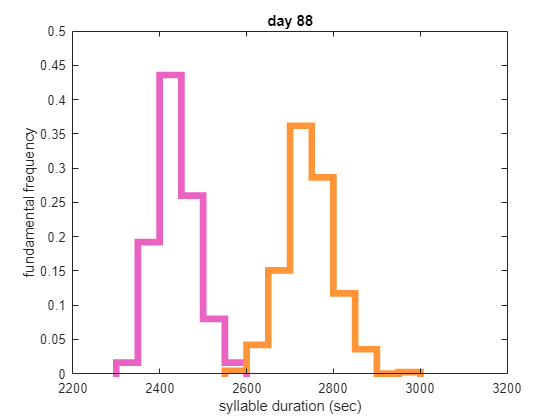

case_ID = 'br177yw112_d1_day88'

case_ID = 'br177yw112_d2_day88'

% Perform k-means clustering using specified number of clusters (K value)
K = 2;
[clusterIndices,centroids] = kmeans(X,K);

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(X);
clusterMeans = grpstats(score,clusterIndices,"mean");
h2 = gscatter(score(:,1),score(:,2),clusterIndices);
for i = 1:numel(h2)
    h2(i).DisplayName = strcat("Cluster",h2(i).DisplayName);
end
clear h2 i score
hold on
h2 = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h2.DisplayName = "ClusterMeans";
clear h2 clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

% Matrix plot
figure
selectedCols = sort([2,1]);
[~,ax] = gplotmatrix(X(:,selectedCols),[],clusterIndices,[],[],[],[],"grpbars");
title("Comparison of Columns in Clustered Data");
clear K
clusterMeans = grpstats(X,clusterIndices,"mean");
hold(ax,"on");
for i = 1 : size(selectedCols,2)
  for j = 1 : size(selectedCols,2)
      if i ~= j  
          scatter(ax(j,i),clusterMeans(:,selectedCols(i)),clusterMeans(:,selectedCols(j)), ...
            50,"kx","LineWidth",1.5,"DisplayName","ClusterMeans");
          xlabel(ax(size(selectedCols,2),i),("Column" + selectedCols(i)));
          ylabel(ax(i,1),("Column" + selectedCols(i)));
      end
   end
end
clear ax clusterMeans i j selectedCols

    % silhouette plot to measure how close each point in one cluster is to points in the neighboring clusters
    [silh3,h] = silhouette(X,clusterIndices,'cityblock');
    xlabel('Silhouette Value')
    ylabel('Cluster')

    % Determine which cluster indices are d1 and d2
    mean1 = mean(f1(clusterIndices==1)); 
    mean2 = mean(f1(clusterIndices==2));

    if mean1 < mean2
        dclust{1} = find(clusterIndices==1);
        dclust{2} = find(clusterIndices==2);
    else 
        dclust{1} = find(clusterIndices==2);
        dclust{2} = find(clusterIndices==1);
    end

    d1clr = '#EA63C2'; %cluster index 1 ORANGE
    d2clr = '#FF9538'; %cluster index 1 MAGENTA

    % check clustering
    figure; pd=histogram(f1(dclust{1}),Normalization='probability',DisplayStyle='stairs',BinWidth=50); 
    xlim([2200 3200]); ylim([0 0.5]); hold on
    pd.EdgeColor = d1clr; pd.LineWidth = 5; hold on
    hold on;pf=histogram(f1(dclust{2}),Normalization='probability',DisplayStyle='stairs',BinWidth=50)
    pf.EdgeColor = d2clr; pf.LineWidth = 5; hold on
    xlabel('syllable duration (sec)');
    ylabel('fundamental frequency');
    dayname = num2str(day);
    title(['day ' dayname(1:2)])

    % duplicate d for d1 and d2
    allCases.(['br177yw112_d1_day' num2str(day)]) = allCases.(['br177yw112_d_day' num2str(day)]);
    allCases.(['br177yw112_d2_day' num2str(day)]) = allCases.(['br177yw112_d_day' num2str(day)]);

    % create variables that split d1 and d2
    dsyl = ['d1';'d2'];
    for i = 1:2
        case_ID = ['br177yw112_' dsyl(i,:) '_day' num2str(day)]
        allCases.(case_ID).recfilename = allCases.(['br177yw112_d_day' num2str(day)]).recfilename(dclust{i});
        allCases.(case_ID).syl_ons_offs = allCases.(['br177yw112_d_day' num2str(day)]).syl_ons_offs(dclust{i});
        allCases.(case_ID).syl_ons_offs_intan = allCases.(['br177yw112_d_day' num2str(day)]).syl_ons_offs_intan(dclust{i});
        allCases.(case_ID).syls_prev = allCases.(['br177yw112_d_day' num2str(day)]).syls_prev(dclust{i});
        allCases.(case_ID).syls_next = allCases.(['br177yw112_d_day' num2str(day)]).syls_next(dclust{i});
        allCases.(case_ID).syl_in_seq = allCases.(['br177yw112_d_day' num2str(day)]).syl_in_seq(dclust{i});
        allCases.(case_ID).spiketrains = allCases.(['br177yw112_d_day' num2str(day)]).spiketrains(dclust{i});
        allCases.(case_ID).spiketrains_intan = allCases.(['br177yw112_d_day' num2str(day)]).spiketrains_intan(dclust{i});
        allCases.(case_ID).weighted_avg_pitch = allCases.(['br177yw112_d_day' num2str(day)]).weighted_avg_pitch(dclust{i});
        allCases.(case_ID).wiener_entropy = allCases.(['br177yw112_d_day' num2str(day)]).wiener_entropy(dclust{i});
        allCases.(case_ID).amplitude = allCases.(['br177yw112_d_day' num2str(day)]).amplitude(dclust{i});
        allCases.(case_ID).t_assay = allCases.(['br177yw112_d_day' num2str(day)]).t_assay(dclust{i});
        allCases.(case_ID).spect_entropy = allCases.(['br177yw112_d_day' num2str(day)]).spect_entropy(dclust{i});
        % allCases.(case_ID).pitch_cont = allCases.(['br177yw112_d_day' num2str(day)]).pitch_cont(dclust{i});
    end

end

savefn = 'compiled_cases_2024_02_20.mat';
save(savefn,"allCases",'-append');

## Run Spike Stats Analysis

Sam's adult data

% load Sam's adult cases
% Load single unit cases (load only subset)
cd J:\Sam_adultRA\
files = "case_ids_1_50"; % SU only, "case_ids_all_1_50" for %SUs + MUs
load("case_ids.mat",files);
samCaseNames = case_ids_1_50;

% Set Params
sam_params.time_window=0.04; % in sec

samStats = analy_motor_win_SamAdult(samCaseNames,sam_params)

samStats = struct with fields:
        mean_fr: [34×1 double]
        entropy: [34×1 double]
        case_sz: [34×1 double]
      casenames: {34×1 cell}
       mean_isi: [34×1 double]
       mean_ifr: [34×1 double]
    fano_factor: [34×1 double]


Leila's adult data

% Load casefiles
cd(targetdir)
loadfn = 'compiled_cases_2024_02_20.mat';
load(loadfn,"allCases","birdname1", "days1", "syls1", "birdname2", "days2", "syls2");

% Extract adult cases in allCases
allFieldNames = fieldnames(allCases); % Get all field names
adultLeilaCases = struct(); % Initialize an empty structure for adultCases

for i = 1:length(allFieldNames)
    fieldName = allFieldNames{i};
    if endsWith(fieldName, '153') % Check if the field name ends with '153'
        adultLeilaCases.(fieldName) = allCases.(fieldName); % Copy the field to adultCases
    end
end

% Run spiking analysis
adult_params.preonset = 0.03;
adult_params.postonset = 0.03;
motor_window = adult_params.preonset + adult_params.postonset; %sec
adult_params.minTrials = 25;
adult_params.minSpikes = 1;

adultLeilaStats = analy_motor_win(adultLeilaCases,adult_params);

plotflag = 0

    {'br173gr56_b_day153'}

    {'br173gr56_c_day153'}

    {'br173gr56_f_day153'}

    {'br173gr56_g_day153'}

    {'br173gr56_h_day153'}

    {'br173gr56_j_day153'}

    {'br173gr56_k_day153'}

    {'br173gr56_p_day153'}

    {'br173gr56_q_day153'}



Combine Sam's and Leila's adult data

adultStats = struct();
adultStats.mean_fr = [adultLeilaStats.mean_fr; samStats.mean_fr];
adultStats.entropy = [adultLeilaStats.entropy; samStats.entropy];
adultStats.case_sz = [adultLeilaStats.case_sz; samStats.case_sz];
adultStats.casenames = [adultLeilaStats.casenames; samStats.casenames];
adultStats.fano_factor = [adultLeilaStats.fano_factor; samStats.fano_factor];

Extract juvenile cases from allCases

% Assume allCases is your original structure
allFieldNames = fieldnames(allCases); % Get all field names
juvCases = struct(); % Initialize an empty structure for juvCases

excludedSuffixes = {'153', 'd_day73', 'd_day86', 'd_day88'}; % List of suffixes to exclude

for i = 1:length(allFieldNames)
    fieldName = allFieldNames{i};
    shouldExclude = false; % Initialize flag to indicate if the field should be excluded
    
    % Check if the field name ends with any of the excluded suffixes
    for j = 1:length(excludedSuffixes)
        if endsWith(fieldName, excludedSuffixes{j})
            shouldExclude = true; % Set flag to true if field ends with an excluded suffix
            break; % Exit the loop since we found a match
        end
    end
    
    % Copy the field to juvCases if it should not be excluded
    if ~shouldExclude
        juvCases.(fieldName) = allCases.(fieldName);
    end
end

Run analysis on juvenile cases

juv_params.preonset = 0.03;
juv_params.postonset = 0.03;
motor_window = juv_params.preonset + juv_params.postonset; %sec
juv_params.minTrials = 25;
juv_params.minSpikes = 1;

% juv_early = analy_motor_win(allCases,juv_params);
juvStats = analy_motor_win(juvCases,juv_params);

plotflag = 0

    {'br177yw112_b_day62'}

    {'br177yw112_c_day62'}

    {'br177yw112_d_day62'}

    {'br177yw112_b_day661'}

    {'br177yw112_c_day661'}

    {'br177yw112_d_day661'}

    {'br177yw112_b_day662'}

    {'br177yw112_c_day662'}

    {'br177yw112_d_day662'}

    {'br177yw112_k_day662'}

    {'br177yw112_r_day662'}

    {'br177yw112_b_day73'}

    {'br177yw112_c_day73'}

    {'br177yw112_g_day73'}

    {'br177yw112_h_day73'}

    {'br177yw112_j_day73'}

    {'br177yw112_k_day73'}

    {'br177yw112_r_day73'}

    {'br177yw112_m_day73'}

    {'br177yw112_b_day86'}

    {'br177yw112_c_day86'}

    {'br177yw112_g_day86'}

    {'br177yw112_h_day86'}

    {'br177yw112_j_day86'}

    {'br177yw112_k_day86'}

    {'br177yw112_r_day86'}

    {'br177yw112_m_day86'}

    {'br177yw112_b_day88'}

    {'br177yw112_c_day88'}

    {'br177yw112_g_day88'}

    {'br177yw112_h_day88'}

    {'br177yw112_j_day88'}

    {'br177yw112_k_day88'}

    {'br177yw112_r_day88'}

    {'br177yw112_m_day88'}

    {'br173g

## PLOT FANO FACTOR AND MEAN FIRING RATES

Plot FF for all syllable cases across time. 

% figct = figct +1;
% figure(figct);clf;hold on
fontname = 'Franklin Gothic Heavy';
spikeStats = juvStats; 

% extract the fano factors for distinct syllables
    filenames = spikeStats.casenames;
    filenames = sort(filenames)

filenames = 61×1 cell array
    {'br173gr56_b_day801'}
    {'br173gr56_b_day811'}
    {'br173gr56_c_day78' }
    {'br173gr56_c_day801'}
    {'br173gr56_c_day802'}
    {'br173gr56_c_day811'}
    {'br173gr56_f_day803'}
    {'br173gr56_f_day811'}
    {'br173gr56_g_day78' }
    {'br173gr56_g_day801'}
    {'br173gr56_g_day803'}
    {'br173gr56_g_day811'}
    {'br173gr56_g_day812'}
    {'br173gr56_h_day78' }
    {'br173gr56_h_day801'}
    {'br173gr56_h_day803'}
    {'br173gr56_h_day811'}
    {'br173gr56_h_day812'}
    {'br173gr56_j_day801'}
    {'br173gr56_k_day78' }
    {'br173gr56_k_day801'}
    {'br173gr56_k_day802'}
    {'br173gr56_p_day803'}
    {'br173gr56_p_day811'}
    {'br173gr56_q_day78' }
    {'br173gr56_q_day801'}
    {'br173gr56_q_day803'}
    {'br173gr56_r_day78' }
    {'br173gr56_s_day78' }
    {'br173gr56_s_day803'}


    % Initialize an empty cell array for the extracted parts
    extractedParts = cell(size(filenames));

    for i = 1:length(filenames)
        filename = filenames{i};
        
        % Find indices of underscores in the filename
        underscoreIndices = strfind(filename, '_');
        extractedParts{i} = filename(1:underscoreIndices(2)-1);
        case_days(i) = str2double(filename(underscoreIndices(2)+4:end));
    end

    % change neuron ID to days
    case_days(case_days == 661) = 66; 
    case_days(case_days == 662) = 66.5; 
    case_days(case_days == 801) = 80;
    case_days(case_days == 802) = 80.3;
    case_days(case_days == 803) = 80.6;
    case_days(case_days == 811) = 81; 
    case_days(case_days == 812) = 81.5; 
    
    % Find unique values and their first index of occurrence
    [uniqueParts, ~, idxUnique] = unique(extractedParts);
    
    % idxUnique now holds indices of extractedParts that map back to the original list of filenames
    % To find the unique indices corresponding to the original list of filenames:
    uniqueIndices = arrayfun(@(x) find(idxUnique == x, 1, 'first'), 1:length(uniqueParts));

    % for each unique syllable, create vectors of the days and the
    % corresponding fano factors
    uniqueSyl = uniqueParts;
        
        % remove 'br177yw112_d' cases
        remove = strcmp(uniqueSyl,'br177yw112_d');
        uniqueSyl(remove) =[]

uniqueSyl = 21×1 cell array
    {'br173gr56_b'  }
    {'br173gr56_c'  }
    {'br173gr56_f'  }
    {'br173gr56_g'  }
    {'br173gr56_h'  }
    {'br173gr56_j'  }
    {'br173gr56_k'  }
    {'br173gr56_p'  }
    {'br173gr56_q'  }
    {'br173gr56_r'  }
    {'br173gr56_s'  }
    {'br177yw112_b' }
    {'br177yw112_c' }
    {'br177yw112_d1'}
    {'br177yw112_d2'}
    {'br177yw112_g' }
    {'br177yw112_h' }
    {'br177yw112_j' }
    {'br177yw112_k' }
    {'br177yw112_m' }
    {'br177yw112_r' }


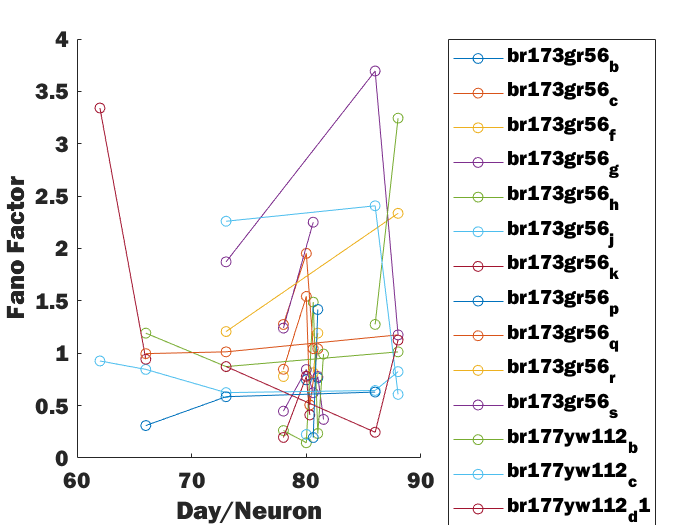

    for ii = 1:length(uniqueSyl)
        uniqueSyl(ii);
        syl_idx = find(idxUnique == ii);
        syl_ffs{ii} = spikeStats.fano_factor(syl_idx);
        syl_frs{ii} = spikeStats.mean_fr(syl_idx);
        syl_casenames{ii} = spikeStats.casenames(syl_idx);
        syl_days{ii} = case_days(syl_idx);
    end

% Plot the fano factor of a distinct syllable over time
figure; hold on
for j = 1:length(uniqueSyl)
    plot(syl_days{j}, syl_ffs{j},'-o')
end
ylabel('Fano Factor')
xlabel('Day/Neuron')
legend(uniqueSyl,Location = "eastoutside")
set(gca,'FontSize',14,'FontName',fontname)
set(gcf,'Visible','On')

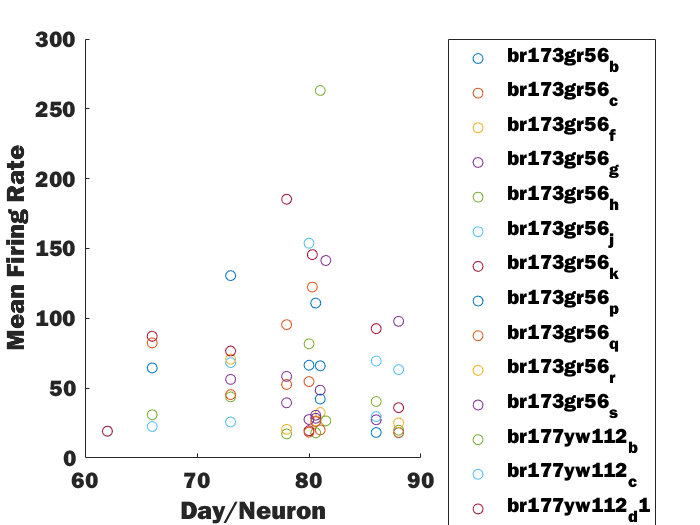



% Plot the mean firing rates
figure; hold on
for j = 1:length(uniqueSyl)
    plot(syl_days{j}, syl_frs{j},'o')
end
ylabel('Mean Firing Rate')
xlabel('Day/Neuron')
legend(uniqueSyl,Location = "eastoutside")
set(gca,'FontSize',14,'FontName',fontname)
set(gcf,'Visible','On')

plot for each bird

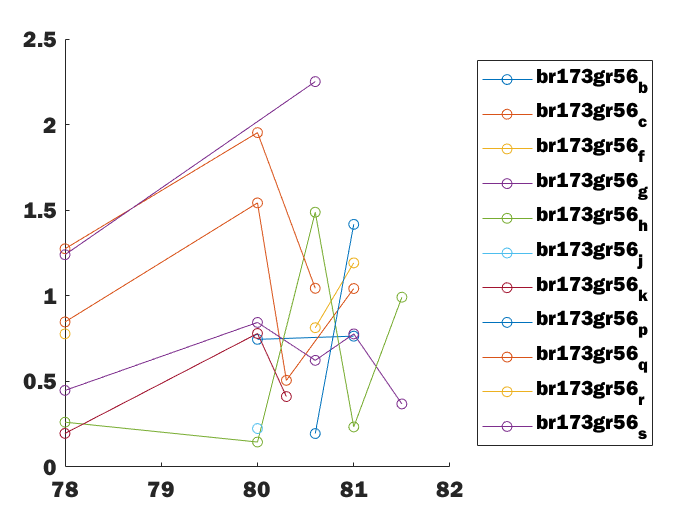

figure; hold on
which = find(contains(uniqueSyl,'br173gr56'));
for jj = 1:length(which)
    curr = which(jj);
    plot(syl_days{curr}, syl_ffs{curr},'-o')
end
legend(uniqueSyl(which),Location = "eastoutside")
set(gca,'FontSize',14,'FontName',fontname)
set(gcf,'Visible','On')

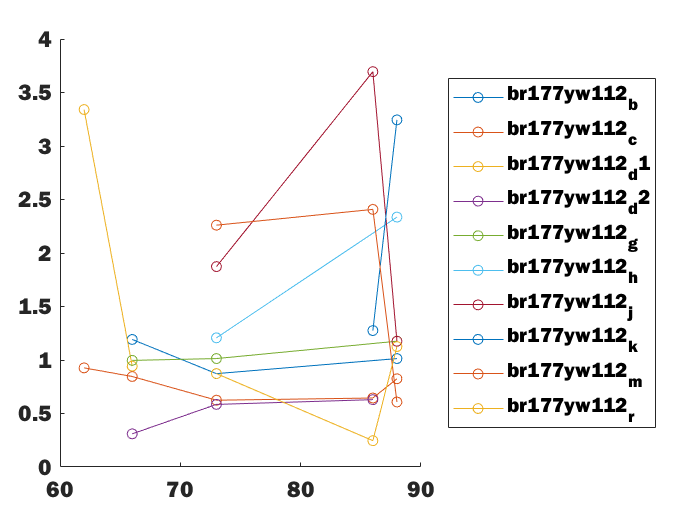


figure; hold on
which = find(contains(uniqueSyl,'br177'));
for jj = 1:length(which)
    curr = which(jj);
    plot(syl_days{curr}, syl_ffs{curr},'-o')
end
legend(uniqueSyl(which),Location = "eastoutside")
set(gca,'FontSize',14,'FontName',fontname)
set(gcf,'Visible','On')


% PLOT for individual syllables
% plotsyls = ["d1"; "d2"]
% for j = 1:length(uniqueSyl)
%     figure; plot(syl_days{j}, syl_ffs{j},'-o', LineWidth=5)
%     title(uniqueSyl(j))
%     xlim([60 90])
%     ylim([0 4])
%     ylabel('Fano Factor')
%     set(gca,'FontSize',20,'FontName',fontname)
% end


Plot fano factor by adult vs juv regardless of spike rate

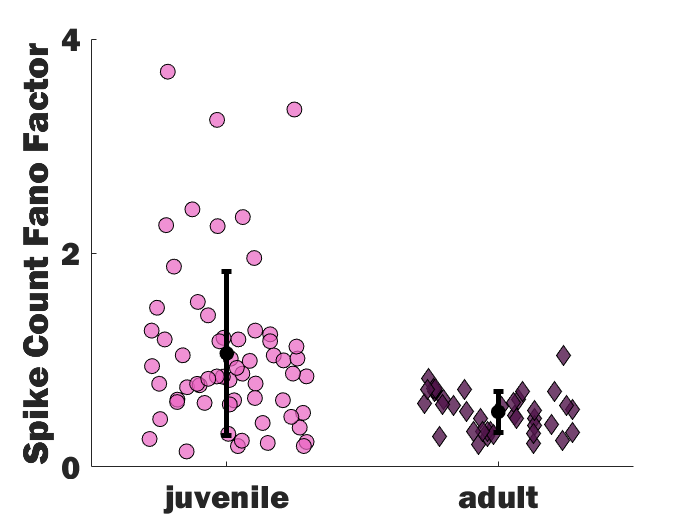

fontname = 'Franklin Gothic Heavy';
% Plot normalized entropies by group
figure(11);clf;hold on
vec1= juvStats.fano_factor;
vec2= adultStats.fano_factor;
vec3= adultStats.fano_factor;
xPlace = [1 2];
b1=scatter(xPlace(1)*ones(1,length(vec1)),vec1,80,'o','jitter','on', 'jitterAmount', 0.3);
b1.MarkerFaceColor = '#EA63C2'; b1.MarkerFaceAlpha = 0.7;
b1.MarkerEdgeColor = 'black';
errorbar(xPlace(1),mean(vec1),std(vec1),std(vec1),'-k.','MarkerSize',30,...
    'MarkerEdgeColor','black','MarkerFaceColor','black', 'LineWidth',3);
% b2=scatter(xPlace(2)*ones(1,length(vec2)),vec2,100,'r.', 'jitter','on', 'jitterAmount', 0.2);
% errorbar(xPlace(2),mean(vec2),std(vec2),std(vec2),'-kx','MarkerSize',15,...
%     'MarkerEdgeColor','black','MarkerFaceColor','black');
b3=scatter(xPlace(2)*ones(1,length(vec3)),vec3,80,'diamond', 'jitter','on', 'jitterAmount', 0.3);
b3.MarkerFaceColor = '#51154B'; b3.MarkerFaceAlpha = 0.8;
b3.MarkerEdgeColor = 'black';
errorbar(xPlace(2),mean(vec3),std(vec3),std(vec3),'-k.','MarkerSize',30,...
    'MarkerEdgeColor','black','MarkerFaceColor','black','LineWidth',3);
xlim([xPlace(1)-0.5 xPlace(2)+0.5])
% ylim([0.2 0.7])
xticks(xPlace)
yticks(0:2:4)
xticklabels({'juvenile';'adult'})
ylabel('Spike Count Fano Factor')
set(gca,'FontSize',20,'FontName',fontname)

set(gcf,'Visible','On')

[h,p,kstest] = kstest2(vec1, vec3)

h = logical
   1


p = 7.3071e-09

kstest = 0.6208

MEAN FIRING RATES - JUV VS ADULT

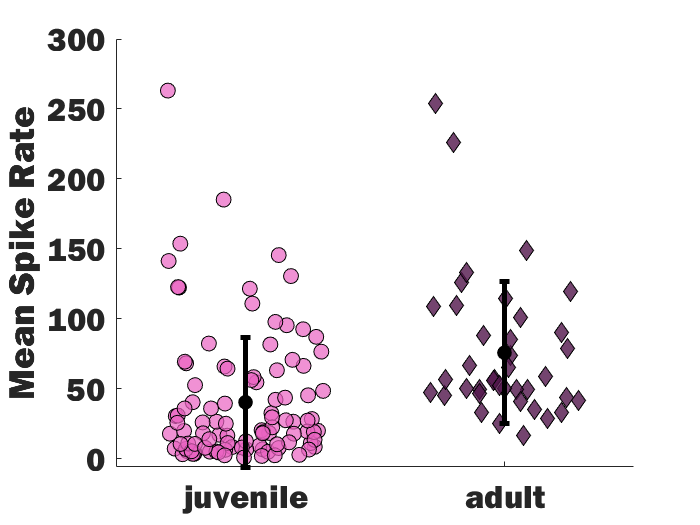

fontname = 'Franklin Gothic Heavy';

figure(12);clf;hold on
vec1= juvStats.mean_fr_all;
vec3= adultStats.mean_fr;
xPlace = [1 2];
b1=scatter(xPlace(1)*ones(1,length(vec1)),vec1,80,'o','jitter','on', 'jitterAmount', 0.3);
b1.MarkerFaceColor = '#EA63C2'; b1.MarkerFaceAlpha = 0.7;
b1.MarkerEdgeColor = 'black';
errorbar(xPlace(1),mean(vec1),std(vec1),std(vec1),'-k.','MarkerSize',30,...
    'MarkerEdgeColor','black','MarkerFaceColor','black', 'LineWidth',3);
b3=scatter(xPlace(2)*ones(1,length(vec3)),vec3,80,'diamond', 'jitter','on', 'jitterAmount', 0.3);
b3.MarkerFaceColor = '#51154B'; b3.MarkerFaceAlpha = 0.8;
b3.MarkerEdgeColor = 'black';
errorbar(xPlace(2),mean(vec3),std(vec3),std(vec3),'-k.','MarkerSize',30,...
    'MarkerEdgeColor','black','MarkerFaceColor','black','LineWidth',3);
xlim([xPlace(1)-0.5 xPlace(2)+0.5])
xticks(xPlace)
% yticks(0:2:4)
xticklabels({'juvenile';'adult'})
ylabel('Mean Spike Rate')
set(gca,'FontSize',20,'FontName',fontname)

set(gcf,'Visible','On')

[h,p,kstest] = kstest2(vec1, vec3)

h = logical
   1


p = 1.9274e-08

kstest = 0.5594

Do juv vs adult neurons spike in a syllable specific way? 

Just plot for syllables c/r

% find the indices for c and r
idx_c = find(strcmp('br177yw112_c',uniqueSyl))

idx_c = 12

uniqueSyl(idx_c)

ans = 1×1 cell array
    {'br177yw112_c'}


idx_r = find(strcmp('br177yw112_r',uniqueSyl))

idx_r = 19

uniqueSyl(idx_r)

ans = 1×1 cell array
    {'br177yw112_r'}


idx_cr = [idx_c idx_r]

idx_cr =     12    19



    for jj = 1:2
        ii = idx_cr(jj);
        uniqueSyl(ii);
        cr_idx = find(idxUnique == ii);
        cr_counts{jj} = spikeStats.spike_counts(syl_idx);
        cr_ffs{jj} = spikeStats.fano_factor(syl_idx);
        cr_casenames{jj} = spikeStats.casenames(syl_idx);
        cr_days{jj} = case_days(syl_idx);
    end

ff_cr = [syl_ffs{1}(1) ff_cr]

Unrecognized function or variable 'ff_cr'.

% recalculate ff for day 
'br177yw112_c_day62'
'br177yw112_c_day661'
'br177yw112_c_day662'
'br177yw112_c_day73'
'br177yw112_c_day86'
'br177yw112_c_day88'
0.967923280423281
1.65694581280788
1.17152103559871
0.823384746174397
0.415685685584626
0.325432759819940

'br177yw112_r_day662'
'br177yw112_r_day73'
'br177yw112_r_day86'
'br177yw112_r_day88'
1.62719298245614
1.06091846298032
0.181992770604048
1.09021837309389

days = [62 66 73 86 88]; 
ff_cr = []

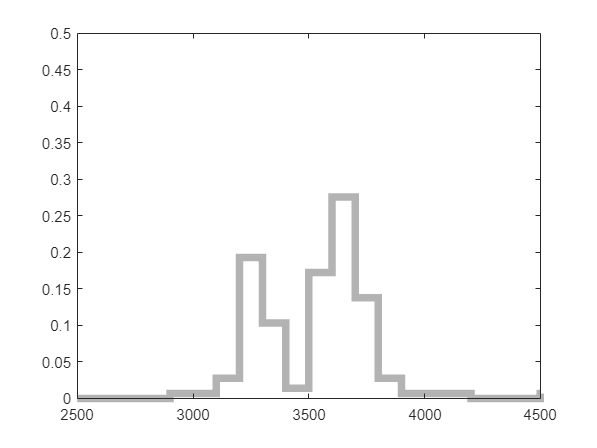

yclr = [.7 .7 .7];
cclr = '#B8CFEB';
rclr = '#4DAF4D';
linewidth = 5;

figure;c62=histogram(allCases.br177yw112_c_day62.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
c62.EdgeColor = [.7 .7 .7]; c62.LineWidth = linewidth;

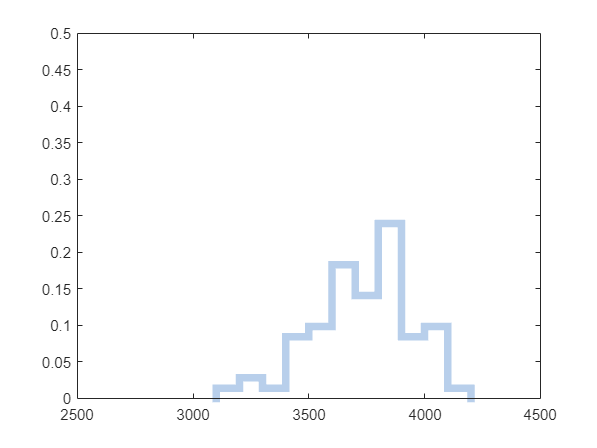


figure;c661=histogram(allCases.br177yw112_c_day661.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
c661.EdgeColor = cclr; c661.LineWidth = 5;
hold on; r661=histogram(allCases.br177yw112_r_day661.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
r661.EdgeColor = rclr; r661.LineWidth = linewidth;

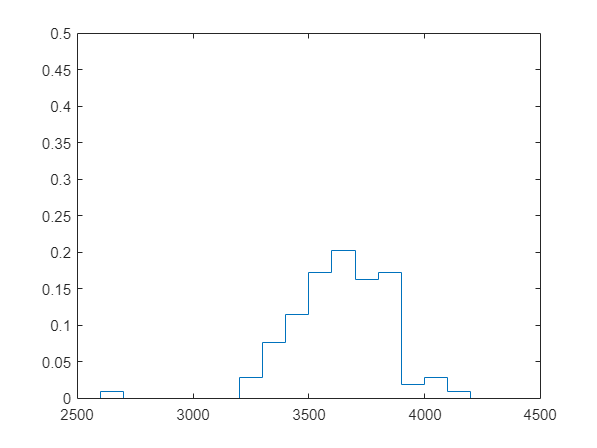


figure;c662=histogram(allCases.br177yw112_c_day662.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
hold on; histogram(allCases.br177yw112_r_day662.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])

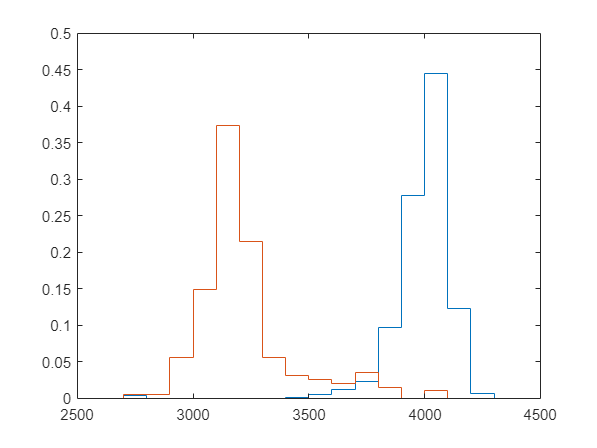

r662.EdgeColor = rclr; r662.LineWidth = linewidth;

figure;p73=histogram(allCases.br177yw112_c_day73.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
hold on; histogram(allCases.br177yw112_r_day73.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])

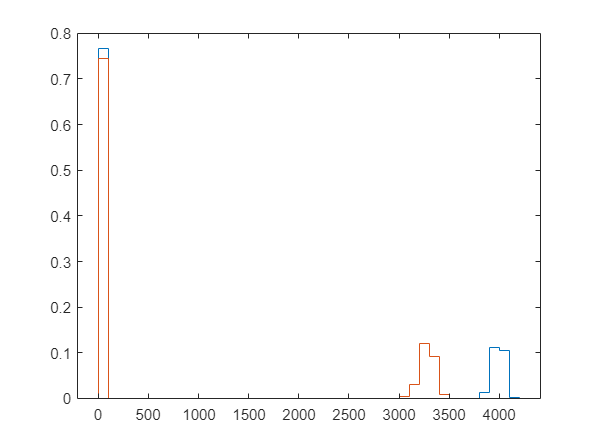


figure;p86=histogram(allCases.br177yw112_c_day86.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); 
% xlim([2500 4500]); ylim([0 0.5])
hold on; histogram(allCases.br177yw112_r_day86.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); 

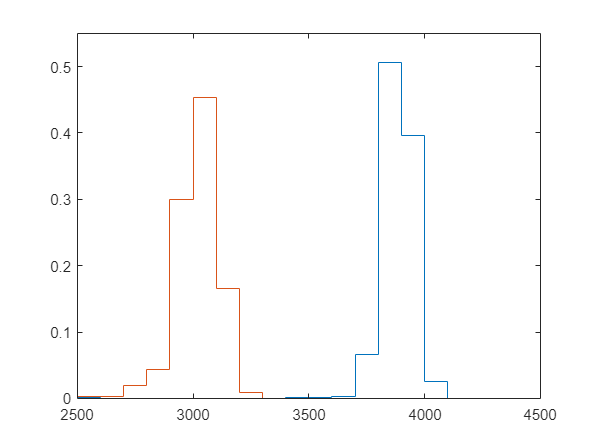

% xlim([2500 4500]); ylim([0 0.5])

figure;p88=histogram(allCases.br177yw112_c_day88.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
hold on; histogram(allCases.br177yw112_r_day88.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.55])

xtix =         3000        4000


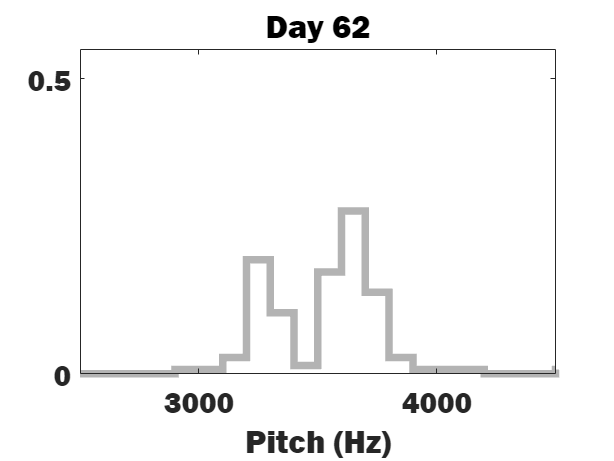

rFieldName = 'br177yw112_r_day62.weighted_avg_pitch'

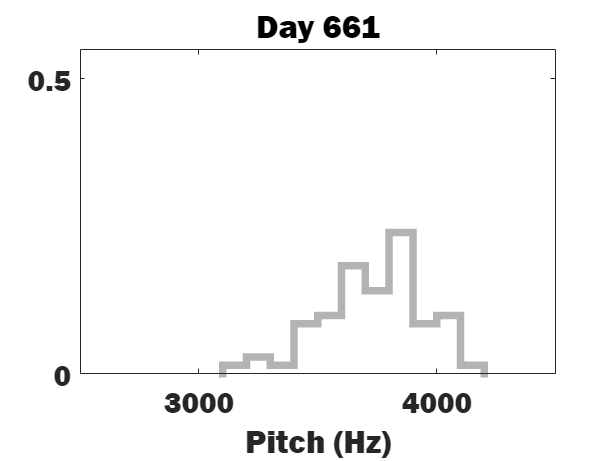

rFieldName = 'br177yw112_r_day661.weighted_avg_pitch'

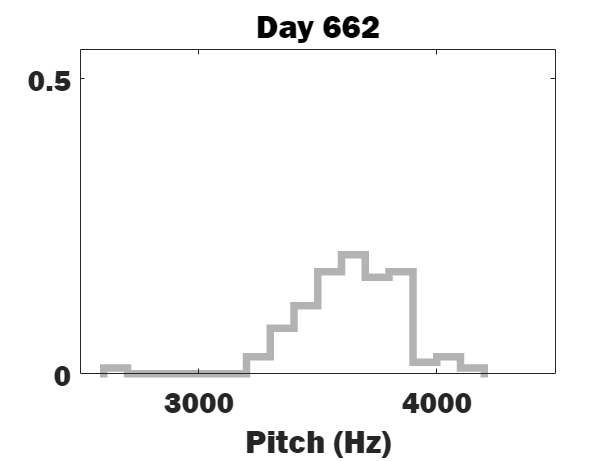

rFieldName = 'br177yw112_r_day662.weighted_avg_pitch'

rFieldName = 'br177yw112_r_day73.weighted_avg_pitch'

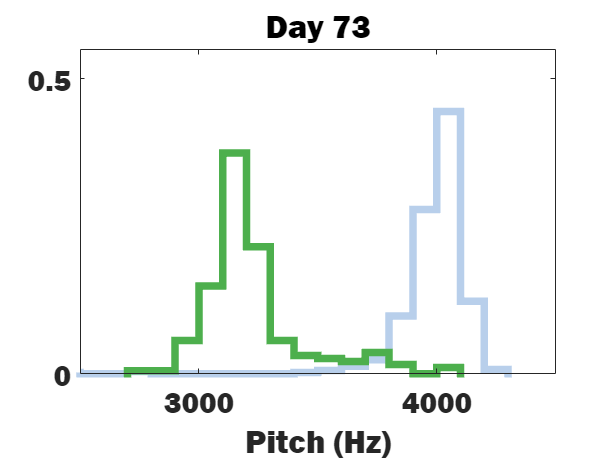

rFieldName = 'br177yw112_r_day86.weighted_avg_pitch'

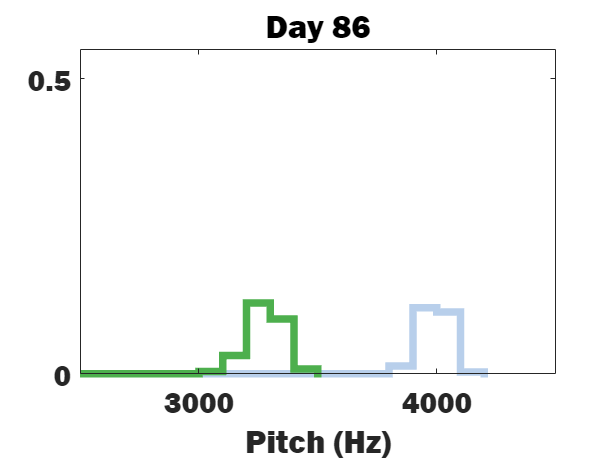

rFieldName = 'br177yw112_r_day88.weighted_avg_pitch'

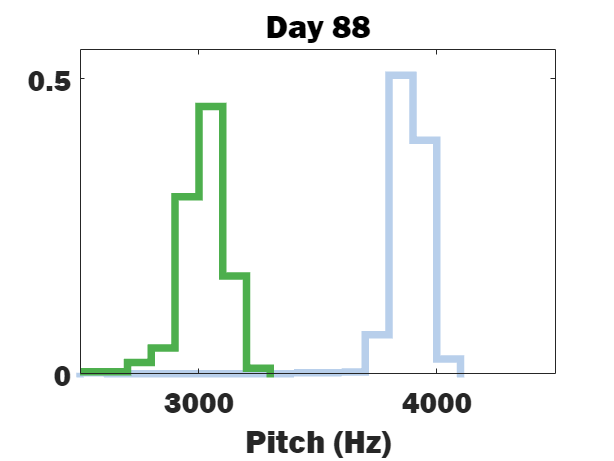

juvCases = struct with fields:
      br177yw112_b_day62: [1×1 struct]
      br177yw112_c_day62: [1×1 struct]
      br177yw112_d_day62: [1×1 struct]
      br177yw112_g_day62: [1×1 struct]
      br177yw112_h_day62: [1×1 struct]
      br177yw112_j_day62: [1×1 struct]
      br177yw112_k_day62: [1×1 struct]
      br177yw112_r_day62: [1×1 struct]
      br177yw112_m_day62: [1×1 struct]
     br177yw112_b_day661: [1×1 struct]
     br177yw112_c_day661: [1×1 struct]
     br177yw112_d_day661: [1×1 struct]
     br177yw112_g_day661: [1×1 struct]
     br177yw112_h_day661: [1×1 struct]
     br177yw112_j_day661: [1×1 struct]
     br177yw112_k_day661: [1×1 struct]
     br177yw112_r_day661: [1×1 struct]
     br177yw112_m_day661: [1×1 struct]
     br177yw112_b_day662: [1×1 struct]
     br177yw112_c_day662: [1×1 struct]
     br177yw112_d_day662: [1×1 struct]
     br177yw112_g_day662: [1×1 struct]
     br177yw112_h_day662: [1×1 struct]
     br177yw112_j_day662: [1×1 struct]
     br177yw112_k_day662: [1×1 st

plotflag = 0

    {'br177yw112_b_day62'}

    {'br177yw112_c_day62'}

    {'br177yw112_d_day62'}

    {'br177yw112_b_day661'}

    {'br177yw112_c_day661'}

    {'br177yw112_d_day661'}

    {'br177yw112_b_day662'}

    {'br177yw112_c_day662'}

    {'br177yw112_d_day662'}

    {'br177yw112_k_day662'}

    {'br177yw112_r_day662'}

    {'br177yw112_b_day73'}

    {'br177yw112_c_day73'}

    {'br177yw112_d_day73'}

    {'br177yw112_g_day73'}

    {'br177yw112_h_day73'}

    {'br177yw112_j_day73'}

    {'br177yw112_k_day73'}

    {'br177yw112_r_day73'}

    {'br177yw112_m_day73'}

    {'br177yw112_b_day86'}

    {'br177yw112_c_day86'}

    {'br177yw112_d_day86'}

    {'br177yw112_g_day86'}

    {'br177yw112_h_day86'}

    {'br177yw112_j_day86'}

    {'br177yw112_k_day86'}

    {'br177yw112_r_day86'}

    {'br177yw112_m_day86'}

    {'br177yw112_b_day88'}

    {'br177yw112_c_day88'}

    {'br177yw112_d_day88'}

    {'br177yw112_g_day88'}

    {'br177yw112_h_day88'}

    {'br177yw112_j_day88'}

    {'br177y

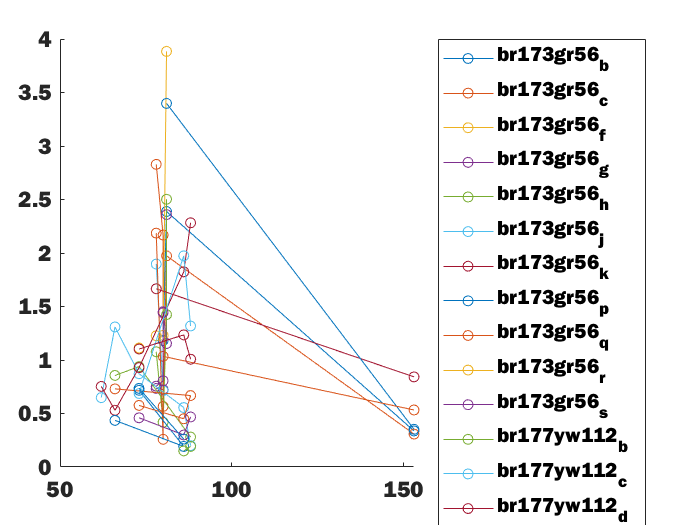

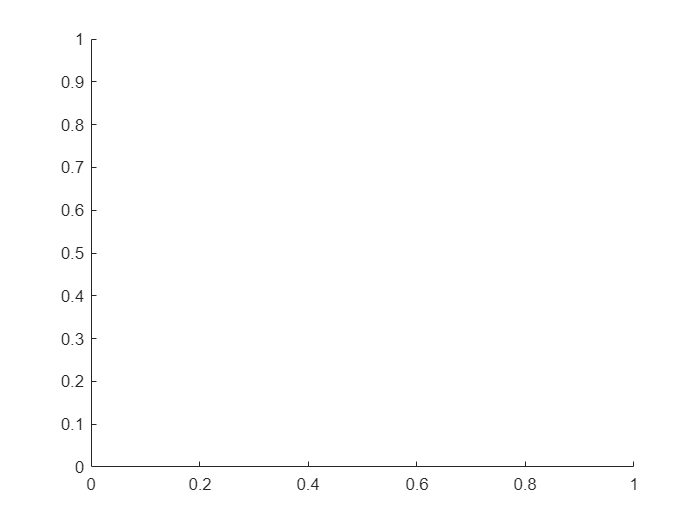

Index exceeds the number of array elements. Index must not exceed 22.

% Colors and linewidth
yclr = [.7 .7 .7];
cclr = '#B8CFEB';
rclr = '#4DAF4D';
linewidth = 5;

% Days to plot
days = [62, 661, 662, 73, 86, 88];

% Call the function with the appropriate parameters
plotHistograms(allCases, days, yclr, cclr, rclr, linewidth);

Plot fano factor by adult vs juv regardless of spike rate

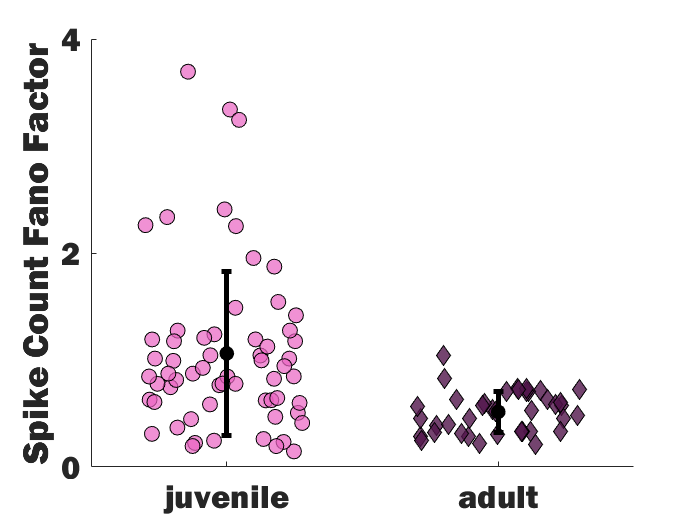

fontname = 'Franklin Gothic Heavy';
% Plot normalized entropies by group
figure(11);clf;hold on
vec1= juvStats.fano_factor;
vec2= adultStats.fano_factor;
vec3= adultStats.fano_factor;
xPlace = [1 2];
b1=scatter(xPlace(1)*ones(1,length(vec1)),vec1,80,'o','jitter','on', 'jitterAmount', 0.3);
b1.MarkerFaceColor = '#EA63C2'; b1.MarkerFaceAlpha = 0.7;
b1.MarkerEdgeColor = 'black';
errorbar(xPlace(1),mean(vec1),std(vec1),std(vec1),'-k.','MarkerSize',30,...
    'MarkerEdgeColor','black','MarkerFaceColor','black', 'LineWidth',3);
% b2=scatter(xPlace(2)*ones(1,length(vec2)),vec2,100,'r.', 'jitter','on', 'jitterAmount', 0.2);
% errorbar(xPlace(2),mean(vec2),std(vec2),std(vec2),'-kx','MarkerSize',15,...
%     'MarkerEdgeColor','black','MarkerFaceColor','black');
b3=scatter(xPlace(2)*ones(1,length(vec3)),vec3,80,'diamond', 'jitter','on', 'jitterAmount', 0.3);
b3.MarkerFaceColor = '#51154B'; b3.MarkerFaceAlpha = 0.8;
b3.MarkerEdgeColor = 'black';
errorbar(xPlace(2),mean(vec3),std(vec3),std(vec3),'-k.','MarkerSize',30,...
    'MarkerEdgeColor','black','MarkerFaceColor','black','LineWidth',3);
xlim([xPlace(1)-0.5 xPlace(2)+0.5])
% ylim([0.2 0.7])
xticks(xPlace)
yticks(0:2:4)
xticklabels({'juvenile';'adult'})
ylabel('Spike Count Fano Factor')
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')


[h,p,kstest] = kstest2(vec1, vec3)

h = logical
   1


p = 7.3071e-09

kstest = 0.6208

Plot Fano Factor by mean rate

Plot Fano Factor for Syllable 'c' and 'r' across days

% undifferentiated syllable 'y'
day62y_idx = strcmp(juvStats.casenames,'br177yw112_c_day62');
day62y_ff = juvStats.fano_factor(day62y_idx)

day62y_ff = 0.7456


% undifferentiated syllable 'c'
day66y_idx = strcmp(juvStats.casenames,'br177yw112_c_day661');
day66y_ff = juvStats.fano_factor(day66y_idx)

day66y_ff = 1.5426


% split day 73 syl c and r
day73c_idx = strcmp(juvStats.casenames,'br177yw112_c_day73');
day73c_ff = juvStats.fano_factor(day73c_idx)

day73c_ff = 0.8136

day73r_idx = strcmp(juvStats.casenames,'br177yw112_r_day73');
day73r_ff = juvStats.fano_factor(day73r_idx)

day73r_ff = 0.6228


% split day 86 syl c and r
day86c_idx = strcmp(juvStats.casenames,'br177yw112_c_day86');
day86c_ff = juvStats.fano_factor(day86c_idx)

day86c_ff = 0.3684

day86r_idx = strcmp(juvStats.casenames,'br177yw112_r_day86');
day86r_ff = juvStats.fano_factor(day86r_idx)

day86r_ff = 0.2340


% split day 88 syl c and r
day88c_idx = strcmp(juvStats.casenames,'br177yw112_c_day88');
day88c_ff = juvStats.fano_factor(day88c_idx)

day88c_ff = 0.1961

Plot b and k across days

% undifferentiated syllable 'x'
% day62_idx = strcmp(juvStats.casenames,'br177yw112_b_day62');
% day62_ff = juvStats.fano_factor(day62_idx)

% undifferentiated syllable 'x'
day66x_idx = strcmp(juvStats.casenames,'br177yw112_b_day661');
day66x_ff = juvStats.fano_factor(day66x_idx)

day66x_ff = 0.8471


% split day 73 syl b and k
day73b_idx = strcmp(juvStats.casenames,'br177yw112_b_day73');
day73b_ff = juvStats.fano_factor(day73b_idx)

day73b_ff = 1.0424

day73k_idx = strcmp(juvStats.casenames,'br177yw112_k_day73');
day73k_ff = juvStats.fano_factor(day73k_idx)

day73k_ff = 0.8444


% split day 86 syl b and k
% day86b_idx = strcmp(juvStats.casenames,'br177yw112_b_day86');
% day86b_ff = juvStats.fano_factor(day86b_idx)
day86k_idx = strcmp(juvStats.casenames,'br177yw112_k_day86');
day86k_ff = juvStats.fano_factor(day86k_idx)

day86k_ff = 1.4882


% split day 88 syl b and k
day88b_idx = strcmp(juvStats.casenames,'br177yw112_b_day88');
day88b_ff = juvStats.fano_factor(day88b_idx)

day88b_ff = 0.2246

day88k_idx = strcmp(juvStats.casenames,'br177yw112_k_day88');
day88k_ff = juvStats.fano_factor(day88k_idx)

day88k_ff = 1.4174

Plot across days

fontname

fontname = 'Arial'

figure; clf; hold on
% Connect the syllables
yclr = [.7 .7 .7];
cclr = '#B8CFEB';
rclr = '#4DAF4D';
xclr = 'k';%'#6BB3B6';
bclr = '#247BB6'

bclr = '#247BB6'

kclr = '#FFC58E'

kclr = '#FFC58E'

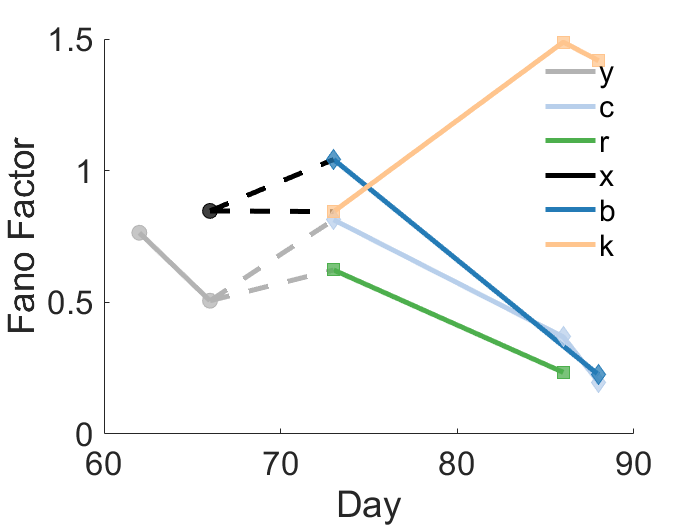


bird1_y_xvals = [62 66];
bird1_c_xvals = [73 86 88];
bird1_r_xvals = [73 86];

bird1_x_xvals = [66];
bird1_b_xvals = [73 88];
bird1_k_xvals = [73 86 88];

bird1_y_yvals = [day62_ff day66_ff];
bird1_c_yvals = [day73c_ff day86c_ff day88c_ff];
bird1_r_yvals = [day73r_ff day86r_ff];

bird1_x_yvals = [day66x_ff];
bird1_b_yvals = [day73b_ff day88b_ff];
bird1_k_yvals = [day73k_ff day86k_ff day88k_ff];

% plot for splitting c and r
plot(bird1_y_xvals, bird1_y_yvals, 'LineWidth', 3, 'Color', yclr); hold on;
plot(bird1_c_xvals, bird1_c_yvals, 'LineWidth', 3, 'Color', cclr);
plot(bird1_r_xvals, bird1_r_yvals, 'LineWidth', 3, 'Color', rclr);

% plot for splitting b and k
plot(bird1_x_xvals, bird1_x_yvals, 'LineWidth', 3, 'Color', xclr); hold on;
plot(bird1_b_xvals, bird1_b_yvals, 'LineWidth', 3, 'Color', bclr);
plot(bird1_k_xvals, bird1_k_yvals, 'LineWidth', 3, 'Color', kclr);

% Adding grey lines with a width of 3
plot([bird1_y_xvals(2), bird1_c_xvals(1)], [bird1_y_yvals(2), bird1_c_yvals(1)], '--', 'Color', [0.7, 0.7, 0.7], 'LineWidth', 3);
plot([bird1_y_xvals(2), bird1_r_xvals(1)], [bird1_y_yvals(2), bird1_r_yvals(1)], '--', 'Color', [0.7, 0.7, 0.7], 'LineWidth', 3);

plot([bird1_x_xvals(1), bird1_b_xvals(1)], [bird1_x_yvals(1), bird1_b_yvals(1)], '--', 'Color', 'k', 'LineWidth', 3);
plot([bird1_x_xvals(1), bird1_k_xvals(1)], [bird1_x_yvals(1), bird1_k_yvals(1)], '--', 'Color', 'k', 'LineWidth', 3);

% Overlay markers with transparency using scatter
scatter(bird1_y_xvals, bird1_y_yvals, 80, 'o', 'filled', 'MarkerFaceColor', yclr, 'MarkerEdgeColor', yclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_c_xvals, bird1_c_yvals, 80, 'd', 'filled', 'MarkerFaceColor', cclr, 'MarkerEdgeColor', cclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_r_xvals, bird1_r_yvals, 80, 's', 'filled', 'MarkerFaceColor', rclr, 'MarkerEdgeColor', rclr, 'MarkerFaceAlpha', 0.75);

scatter(bird1_x_xvals, bird1_x_yvals, 80, 'o', 'filled', 'MarkerFaceColor', xclr, 'MarkerEdgeColor', xclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_b_xvals, bird1_b_yvals, 80, 'd', 'filled', 'MarkerFaceColor', bclr, 'MarkerEdgeColor', bclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_k_xvals, bird1_k_yvals, 80, 's', 'filled', 'MarkerFaceColor', kclr, 'MarkerEdgeColor', kclr, 'MarkerFaceAlpha', 0.75);
hold off;

% Add legend and labels as necessary
xlabel('Day');
ylabel('Fano Factor');
legend({'y','c','r','x','b','k'},"box",'off')

xlim([60 90])
ylim([0 1.5])
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')

Plot Fano Factor for Syllable 'd' splitting to 'd1' and 'd2' across days

% undifferentiated syllable 'd'
day62d_idx = strcmp(juvStats.casenames,'br177yw112_d_day62');
day62d_ff = juvStats.fano_factor(day62d_idx)

day62d_ff = 0.7643


% undifferentiated syllable 'd'
day66d_idx = strcmp(juvStats.casenames,'br177yw112_d_day661');
day66d_ff = juvStats.fano_factor(day66d_idx)

day66d_ff = 0.5060


% split day 73 syl d1 and d2
day73d1_idx = strcmp(juvStats.casenames,'br177yw112_d1_day73');
day73d1_ff = juvStats.fano_factor(day73d1_idx)

day73d1_ff = 0.6074

day73d2_idx = strcmp(juvStats.casenames,'br177yw112_d2_day73');
day73d2_ff = juvStats.fano_factor(day73d2_idx)

day73d2_ff = 0.8731


% split day 86 syl d1 and d2
day86d1_idx = strcmp(juvStats.casenames,'br177yw112_d1_day86');
day86d1_ff = juvStats.fano_factor(day86d1_idx)

day86d1_ff = 0.2458

% day86d2_idx = strcmp(juvStats.casenames,'br177yw112_d2_day86');
% day86d2_ff = juvStats.fano_factor(day86d2_idx)

% % split day 88 syl c and r
day88d2_idx = strcmp(juvStats.casenames,'br177yw112_d2_day88');
day88d2_ff = juvStats.fano_factor(day88d2_idx)

day88d2_ff = 1.1254

Plot across days

fontname

fontname = 'Franklin Gothic Heavy'

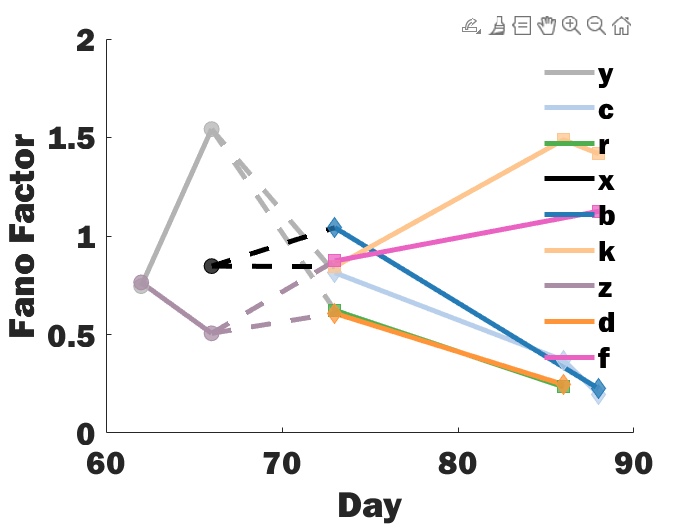

figure; clf; hold on
% Connect the syllables
yclr = [.7 .7 .7];
cclr = '#B8CFEB';
rclr = '#4DAF4D';
xclr = 'k';%'#6BB3B6';
bclr = '#247BB6';
kclr = '#FFC58E';
dclr = '#A98EA5';
d1clr = '#FF9538';
d2clr = '#EA63C2';

bird1_y_xvals = [62 66];
bird1_c_xvals = [73 86 88];
bird1_r_xvals = [73 86];

bird1_x_xvals = [66];
bird1_b_xvals = [73 88];
bird1_k_xvals = [73 86 88];

bird1_d_xvals = [62 66];
bird1_d1_xvals = [73 86];
bird1_d2_xvals = [73 88];

bird1_y_yvals = [day62y_ff day66y_ff];
bird1_c_yvals = [day73c_ff day86c_ff day88c_ff];
bird1_r_yvals = [day73r_ff day86r_ff];

bird1_x_yvals = [day66x_ff];
bird1_b_yvals = [day73b_ff day88b_ff];
bird1_k_yvals = [day73k_ff day86k_ff day88k_ff];

bird1_d_yvals = [day62d_ff day66d_ff];
bird1_d1_yvals = [day73d1_ff day86d1_ff];
bird1_d2_yvals = [day73d2_ff day88d2_ff];


% plot for splitting c and r
plot(bird1_y_xvals, bird1_y_yvals, 'LineWidth', 3, 'Color', yclr); hold on;
plot(bird1_c_xvals, bird1_c_yvals, 'LineWidth', 3, 'Color', cclr);
plot(bird1_r_xvals, bird1_r_yvals, 'LineWidth', 3, 'Color', rclr);

% plot for splitting b and k
plot(bird1_x_xvals, bird1_x_yvals, 'LineWidth', 3, 'Color', xclr); hold on;
plot(bird1_b_xvals, bird1_b_yvals, 'LineWidth', 3, 'Color', bclr);
plot(bird1_k_xvals, bird1_k_yvals, 'LineWidth', 3, 'Color', kclr);

% plot for splitting d
plot(bird1_d_xvals, bird1_d_yvals, 'LineWidth', 3, 'Color', dclr); hold on;
plot(bird1_d1_xvals, bird1_d1_yvals, 'LineWidth', 3, 'Color', d1clr);
plot(bird1_d2_xvals, bird1_d2_yvals, 'LineWidth', 3, 'Color', d2clr);

% Adding grey lines with a width of 3
plot([bird1_y_xvals(2), bird1_c_xvals(1)], [bird1_y_yvals(2), bird1_c_yvals(1)], '--', 'Color', [0.7, 0.7, 0.7], 'LineWidth', 3);
plot([bird1_y_xvals(2), bird1_r_xvals(1)], [bird1_y_yvals(2), bird1_r_yvals(1)], '--', 'Color', [0.7, 0.7, 0.7], 'LineWidth', 3);

plot([bird1_x_xvals(1), bird1_b_xvals(1)], [bird1_x_yvals(1), bird1_b_yvals(1)], '--', 'Color', 'k', 'LineWidth', 3);
plot([bird1_x_xvals(1), bird1_k_xvals(1)], [bird1_x_yvals(1), bird1_k_yvals(1)], '--', 'Color', 'k', 'LineWidth', 3);

plot([bird1_d_xvals(2), bird1_d1_xvals(1)], [bird1_d_yvals(2), bird1_d1_yvals(1)], '--', 'Color', dclr, 'LineWidth', 3);
plot([bird1_d_xvals(2), bird1_d2_xvals(1)], [bird1_d_yvals(2), bird1_d2_yvals(1)], '--', 'Color', dclr, 'LineWidth', 3);

% Overlay markers with transparency using scatter
scatter(bird1_y_xvals, bird1_y_yvals, 80, 'o', 'filled', 'MarkerFaceColor', yclr, 'MarkerEdgeColor', yclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_c_xvals, bird1_c_yvals, 80, 'd', 'filled', 'MarkerFaceColor', cclr, 'MarkerEdgeColor', cclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_r_xvals, bird1_r_yvals, 80, 's', 'filled', 'MarkerFaceColor', rclr, 'MarkerEdgeColor', rclr, 'MarkerFaceAlpha', 0.75);

scatter(bird1_x_xvals, bird1_x_yvals, 80, 'o', 'filled', 'MarkerFaceColor', xclr, 'MarkerEdgeColor', xclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_b_xvals, bird1_b_yvals, 80, 'd', 'filled', 'MarkerFaceColor', bclr, 'MarkerEdgeColor', bclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_k_xvals, bird1_k_yvals, 80, 's', 'filled', 'MarkerFaceColor', kclr, 'MarkerEdgeColor', kclr, 'MarkerFaceAlpha', 0.75);

scatter(bird1_d_xvals, bird1_d_yvals, 80, 'o', 'filled', 'MarkerFaceColor', dclr, 'MarkerEdgeColor', dclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_d1_xvals, bird1_d1_yvals, 80, 'd', 'filled', 'MarkerFaceColor', d1clr, 'MarkerEdgeColor', d1clr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_d2_xvals, bird1_d2_yvals, 80, 's', 'filled', 'MarkerFaceColor', d2clr, 'MarkerEdgeColor', d2clr, 'MarkerFaceAlpha', 0.75);
hold off;

% Add legend and labels as necessary
xlabel('Day');
ylabel('Fano Factor');
legend({'y','c','r','x','b','k','z','d','f'},"box",'off')

xlim([60 90])
ylim([0 2])
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')

## PLOT MEAN FIRING RATE INSTEAD OF FANO FACTOR

% Plot Mean Firing Rate for Syllable 'c' and 'r' across days

% undifferentiated syllable 'y'
day62y_idx = strcmp(juvStats.casenames,'br177yw112_c_day62');
day62y_mfr = juvStats.mean_fr(day62y_idx);

% undifferentiated syllable 'c'
day66y_idx = strcmp(juvStats.casenames,'br177yw112_c_day661');
day66y_mfr = juvStats.mean_fr(day66y_idx);

% split day 73 syl c and r
day73c_idx = strcmp(juvStats.casenames,'br177yw112_c_day73');
day73c_mfr = juvStats.mean_fr(day73c_idx);
day73r_idx = strcmp(juvStats.casenames,'br177yw112_r_day73');
day73r_mfr = juvStats.mean_fr(day73r_idx);

% split day 86 syl c and r
day86c_idx = strcmp(juvStats.casenames,'br177yw112_c_day86');
day86c_mfr = juvStats.mean_fr(day86c_idx);
day86r_idx = strcmp(juvStats.casenames,'br177yw112_r_day86');
day86r_mfr = juvStats.mean_fr(day86r_idx);

% split day 88 syl c and r
day88c_idx = strcmp(juvStats.casenames,'br177yw112_c_day88');
day88c_mfr = juvStats.mean_fr(day88c_idx);

% Plot b and k across days

% undifferentiated syllable 'x'
day66x_idx = strcmp(juvStats.casenames,'br177yw112_b_day661');
day66x_mfr = juvStats.mean_fr(day66x_idx);

% split day 73 syl b and k
day73b_idx = strcmp(juvStats.casenames,'br177yw112_b_day73');
day73b_mfr = juvStats.mean_fr(day73b_idx);
day73k_idx = strcmp(juvStats.casenames,'br177yw112_k_day73');
day73k_mfr = juvStats.mean_fr(day73k_idx);

% split day 86 syl b and k
day86k_idx = strcmp(juvStats.casenames,'br177yw112_k_day86');
day86k_mfr = juvStats.mean_fr(day86k_idx);

% split day 88 syl b and k
day88b_idx = strcmp(juvStats.casenames,'br177yw112_b_day88');
day88b_mfr = juvStats.mean_fr(day88b_idx);
day88k_idx = strcmp(juvStats.casenames,'br177yw112_k_day88');
day88k_mfr = juvStats.mean_fr(day88k_idx);


Plot across days

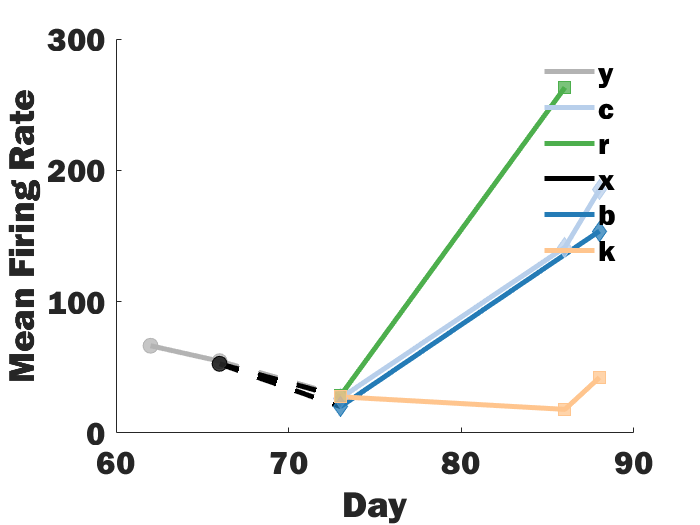

% Plot Mean Firing Rate across days
fontname = 'Franklin Gothic Heavy';
figure; clf; hold on;
% Define colors for each syllable
yclr = [.7 .7 .7];
cclr = '#B8CFEB';
rclr = '#4DAF4D';
xclr = 'k'; % '#6BB3B6';
bclr = '#247BB6';
kclr = '#FFC58E';

% Define x values for each bird and syllable
bird1_y_xvals = [62 66];
bird1_c_xvals = [73 86 88];
bird1_r_xvals = [73 86];
bird1_x_xvals = [66];
bird1_b_xvals = [73 88];
bird1_k_xvals = [73 86 88];

% Update here with mean firing rate values
bird1_y_yvals = [day62y_mfr day66y_mfr];
bird1_c_yvals = [day73c_mfr day86c_mfr day88c_mfr];
bird1_r_yvals = [day73r_mfr day86r_mfr];
bird1_x_yvals = [day66x_mfr];
bird1_b_yvals = [day73b_mfr day88b_mfr];
bird1_k_yvals = [day73k_mfr day86k_mfr day88k_mfr];

% Plot for syllables c and r
plot(bird1_y_xvals, bird1_y_yvals, 'LineWidth', 3, 'Color', yclr); hold on;
plot(bird1_c_xvals, bird1_c_yvals, 'LineWidth', 3, 'Color', cclr);
plot(bird1_r_xvals, bird1_r_yvals, 'LineWidth', 3, 'Color', rclr);

% Plot for syllables b and k
plot(bird1_x_xvals, bird1_x_yvals, 'LineWidth', 3, 'Color', xclr); hold on;
plot(bird1_b_xvals, bird1_b_yvals, 'LineWidth', 3, 'Color', bclr);
plot(bird1_k_xvals, bird1_k_yvals, 'LineWidth', 3, 'Color', kclr);

% Adding grey and black dashed lines
plot([bird1_y_xvals(2), bird1_c_xvals(1)], [bird1_y_yvals(2), bird1_c_yvals(1)], '--', 'Color', [0.7, 0.7, 0.7], 'LineWidth', 3);
plot([bird1_y_xvals(2), bird1_r_xvals(1)], [bird1_y_yvals(2), bird1_r_yvals(1)], '--', 'Color', [0.7, 0.7, 0.7], 'LineWidth', 3);
plot([bird1_x_xvals(1), bird1_b_xvals(1)], [bird1_x_yvals(1), bird1_b_yvals(1)], '--', 'Color', 'k', 'LineWidth', 3);
plot([bird1_x_xvals(1), bird1_k_xvals(1)], [bird1_x_yvals(1), bird1_k_yvals(1)], '--', 'Color', 'k', 'LineWidth', 3);

% Overlay markers with transparency using scatter
scatter(bird1_y_xvals, bird1_y_yvals, 80, 'o', 'filled', 'MarkerFaceColor', yclr, 'MarkerEdgeColor', yclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_c_xvals, bird1_c_yvals, 80, 'd', 'filled', 'MarkerFaceColor', cclr, 'MarkerEdgeColor', cclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_r_xvals, bird1_r_yvals, 80, 's', 'filled', 'MarkerFaceColor', rclr, 'MarkerEdgeColor', rclr, 'MarkerFaceAlpha', 0.75);

scatter(bird1_x_xvals, bird1_x_yvals, 80, 'o', 'filled', 'MarkerFaceColor', xclr, 'MarkerEdgeColor', xclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_b_xvals, bird1_b_yvals, 80, 'd', 'filled', 'MarkerFaceColor', bclr, 'MarkerEdgeColor', bclr, 'MarkerFaceAlpha', 0.75);
scatter(bird1_k_xvals, bird1_k_yvals, 80, 's', 'filled', 'MarkerFaceColor', kclr, 'MarkerEdgeColor', kclr, 'MarkerFaceAlpha', 0.75);

hold off;

% Add legend and labels as necessary
xlabel('Day');
ylabel('Mean Firing Rate');
legend({'y','c','r','x','b','k'},"box",'off')

xlim([60 90])
% ylim([0 2])
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')

Plot fano factor by grouping adults vs juveniles by spike rate

%Adult
s2=scatter(mature.mean_fr,mature.fano_factor,80,'filled','diamond','MarkerFaceAlpha',0.7);

Unable to resolve the name 'mature.mean_fr'.

s2.MarkerFaceColor = '#51154B';
%Juveniles
s3=scatter(juv_early.mean_fr,juv_early.fano_factor,80,'filled','o','MarkerFaceAlpha',0.7);
s3.MarkerFaceColor = '#EA63C2';

xlabel('Spike Rate (Hz)')
ylabel('FanoFactor')
legend({'adult';'juvenile'},"Location","northeast")
legend('boxoff')
% ylim([0 4])
% xlim([0 300])
% title(['Entropy v Spike rates in ' num2str(motor_window*1000) ' ms'])
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')

function plotHistograms(allCases, days, yclr, cclr, rclr, linewidth)
    % Define common plotting parameters
    xlims = [2500 4500];
    ylims = [0 0.55];
    binWidth = 100;
    normalization = 'probability';
    displayStyle = 'stairs';
    ytix = [0 0.5];
    xtix = [3000 4000]
    fontname = 'Franklin Gothic Heavy';
    
    for i = 1:length(days)
        figure;
        day = days(i);

        if day==62|day==661|day==662
            color = yclr; % Use 'yclr' for 'y' cases
        else
            color = cclr; % Use 'cclr' for 'c' cases
        end
        
        % Plot for 'c' cases
        cData = allCases.(['br177yw112_c_day' num2str(day)]).weighted_avg_pitch;
        cHist = histogram(cData, 'BinWidth', binWidth, 'Normalization', normalization, 'DisplayStyle', displayStyle);
        cHist.EdgeColor = color; 
        cHist.LineWidth = linewidth;
        xlabel('Pitch (Hz)')
        xlim(xlims);
        ylim(ylims);
        yticks(ytix);
        xticks(xtix);
        title(['Day ' num2str(day)])
        set(gca,'FontSize',20,'FontName',fontname)
        hold on;
        
        % Check if 'r' data exists for the day
        rFieldName = ['br177yw112_r_day' num2str(day) '.weighted_avg_pitch']
        if day==68|day==73|day==86|day==88
            % rData = allCases.(rFieldName);
            rData = allCases.(['br177yw112_r_day' num2str(day)]).weighted_avg_pitch;
            rHist = histogram(rData, 'BinWidth', binWidth, 'Normalization', normalization, 'DisplayStyle', displayStyle);
            rHist.EdgeColor = rclr; % Use 'rclr' for 'r' cases
            rHist.LineWidth = linewidth;
        end
        
    end
end
